# Data Processing - Remove Regeneration - ARIMA 분석 - #5 #6을 사용하자

clear % 이전 그래프는 지우지 않는다.
close all %  이전 그래프는 지운다.
load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat

load B0029.mat
load B0030.mat
load B0031.mat
load B0032.mat

load B0033.mat
load B0034.mat
load B0036.mat

cap05 = extract_discharge(B0005);
cap06 = extract_discharge(B0006);
cap07 = extract_discharge(B0007);
cap18 = extract_discharge(B0018);

cap29  = extract_discharge(B0029);
cap30  = extract_discharge(B0030);
cap31  = extract_discharge(B0031);
cap32  = extract_discharge(B0032);

cap33 = extract_discharge(B0033);
cap34 = extract_discharge(B0034);
cap36 = extract_discharge(B0036);

% A set of four Li-ion batteries (# 5, 6, 7 and 18) 
% were run through 3 different operational profiles (charge, discharge and impedance) at room temperature. 
% Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V 
% and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. 
% Discharge was carried out at a constant current (CC) level of 2A 
% until the battery voltage fell to 2.7V, 2.5V, 2.2V and 2.5V for batteries 5 6 7 and 18 respectively. 
% Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. Repeated charge and discharge cycles result in accelerated aging of the batteries while impedance measurements provide insight into the internal battery parameters that change as aging progresses. The experiments were stopped when the batteries reached end-of-life (EOL) criteria, which was a 30% fade in rated capacity (from 2Ahr to 1.4Ahr). This dataset can be used for the prediction of both remaining charge (for a given discharge cycle) and remaining useful life (RUL).


%result = [cap',cycleTimeHour',restTimeHour',restCycle',cCCEndTimeSec',cTempMaxDt',cCcEndTimeSec',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe',dTempMax',dTempMaxDt',dCcEndTimeSec' ];
%result = [cap',cycleTimeHourHour',restTimeHourHour',restCycle',cTempMax',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe',dTempMax',cCcEndTimeSec',dCcEndTimeSec' ];
%result = [cap',cycleTimeHour',restTimeHour',restCycle',cTempMax',cCcEndTimeSec',dTempMax',dCcEndTimeSec',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe' ];

i=1;
capacityIdx = i; i=i+1;
cycleTimeHourIdx = i; i=i+1;
restTimeHourIdx = i; i=i+1;
restCycleIdx = i; i=i+1;
cTempMaxIdx = i; i=i+1;
cCcEndTimeSecIdx = i; i=i+1;
dTempMaxIdx = i; i=i+1;
dCcEndTimeSecIdx = i; i=i+1;
ohmIdx = i; i=i+1;
re_cIdx = i; i=i+1;
re_dIdx = i; i=i+1;
cycleNoChageReIdx = i; i=i+1;
cycleNoDischageReIdx = i; i=i+1;
pattern_dVoltIdx = i; i=i+1;
pattern_tempdx = i; i=i+1;
pattern_CC_ampsIdx = i; i=i+1;

pattern_temp05_const = 24;
pattern_temp06_const = 24;
pattern_temp07_const = 24;
pattern_temp18_const = 24;
pattern_temp29_const = 43;
pattern_temp30_const = 43;
pattern_temp31_const = 43;
pattern_temp32_const = 43;
pattern_temp33_const = 24;
pattern_temp34_const = 24;
pattern_temp36_const = 24;

pattern_CC_amps05_const = 2;
pattern_CC_amps06_const = 2;
pattern_CC_amps07_const = 2;
pattern_CC_amps18_const = 2;
pattern_CC_amps29_const = 4;
pattern_CC_amps30_const = 4;
pattern_CC_amps31_const = 4;
pattern_CC_amps32_const = 4;
pattern_CC_amps33_const = 4;
pattern_CC_amps34_const = 4;
pattern_CC_amps36_const = 2;

pattern_dVolt05_const = 4.2 - 2.7 ; 
pattern_dVolt06_const = 4.2 - 2.5 ; 
pattern_dVolt07_const = 4.2 - 2.2 ; 
pattern_dVolt18_const = 4.2 - 2.5 ; 
pattern_dVolt29_const = 4.2 - 2.0 ;   
pattern_dVolt30_const = 4.2 - 2.2 ;   
pattern_dVolt31_const = 4.2 - 2.5 ;   
pattern_dVolt32_const = 4.2 - 2.7 ;   
pattern_dVolt33_const = 4.2 - 2.0 ; 
pattern_dVolt34_const = 4.2 - 2.2 ; 
pattern_dVolt36_const = 4.2 - 2.7 ; 



result_05 = extract_feature_all_v2(B0005,0,cap05);
result_06 = extract_feature_all_v2(B0006,0,cap06);
result_07 = extract_feature_all_v2(B0007,0,cap07);
result_18 = extract_feature_all_v2(B0018,0,cap18);
result_29 = extract_feature_all_v2(B0029,0,cap29);
result_30 = extract_feature_all_v2(B0030,0,cap30);
result_31 = extract_feature_all_v2(B0031,0,cap31);
result_32 = extract_feature_all_v2(B0032,0,cap32);
result_33 = extract_feature_all_v2(B0033,0,cap33);
result_34 = extract_feature_all_v2(B0034,0,cap34);
result_36 = extract_feature_all_v2(B0036,0,cap36);



pattern_dVolt_vector   = ones(length(result_05),1) *  pattern_dVolt05_const; result_05 = [result_05,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_06),1) *  pattern_dVolt06_const; result_06 = [result_06,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_07),1) *  pattern_dVolt07_const; result_07 = [result_07,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_18),1) *  pattern_dVolt18_const; result_18 = [result_18,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_29),1) *  pattern_dVolt29_const; result_29 = [result_29,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_30),1) *  pattern_dVolt30_const; result_30 = [result_30,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_31),1) *  pattern_dVolt31_const; result_31 = [result_31,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_32),1) *  pattern_dVolt32_const; result_32 = [result_32,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_33),1) *  pattern_dVolt33_const; result_33 = [result_33,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_34),1) *  pattern_dVolt34_const; result_34 = [result_34,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_36),1) *  pattern_dVolt36_const; result_36 = [result_36,pattern_dVolt_vector];

pattern_temp_vector   = ones(length(result_05),1) *  pattern_temp05_const; result_05 = [result_05,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_06),1) *  pattern_temp06_const; result_06 = [result_06,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_07),1) *  pattern_temp07_const; result_07 = [result_07,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_18),1) *  pattern_temp18_const; result_18 = [result_18,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_29),1) *  pattern_temp29_const; result_29 = [result_29,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_30),1) *  pattern_temp30_const; result_30 = [result_30,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_31),1) *  pattern_temp31_const; result_31 = [result_31,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_32),1) *  pattern_temp32_const; result_32 = [result_32,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_33),1) *  pattern_temp33_const; result_33 = [result_33,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_34),1) *  pattern_temp34_const; result_34 = [result_34,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_36),1) *  pattern_temp36_const; result_36 = [result_36,pattern_temp_vector];


pattern_CC_amps_vector   = ones(length(result_05),1) *  pattern_CC_amps05_const; result_05 = [result_05,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_06),1) *  pattern_CC_amps06_const; result_06 = [result_06,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_07),1) *  pattern_CC_amps07_const; result_07 = [result_07,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_18),1) *  pattern_CC_amps18_const; result_18 = [result_18,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_29),1) *  pattern_CC_amps29_const; result_29 = [result_29,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_30),1) *  pattern_CC_amps30_const; result_30 = [result_30,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_31),1) *  pattern_CC_amps31_const; result_31 = [result_31,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_32),1) *  pattern_CC_amps32_const; result_32 = [result_32,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_33),1) *  pattern_CC_amps33_const; result_33 = [result_33,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_34),1) *  pattern_CC_amps34_const; result_34 = [result_34,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_36),1) *  pattern_CC_amps36_const; result_36 = [result_36,pattern_CC_amps_vector];

%% remove rest cycle 
restCycleTF_raw_index = find (result_05(:,restCycleIdx) == 1 )'; result_05(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_06(:,restCycleIdx) == 1 )'; result_06(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_07(:,restCycleIdx) == 1 )'; result_07(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_18(:,restCycleIdx) == 1 )'; result_18(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_29(:,restCycleIdx) == 1 )'; result_29(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_30(:,restCycleIdx) == 1 )'; result_30(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_31(:,restCycleIdx) == 1 )'; result_31(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_32(:,restCycleIdx) == 1 )'; result_32(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_33(:,restCycleIdx) == 1 )'; result_33(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_34(:,restCycleIdx) == 1 )'; result_34(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_36(:,restCycleIdx) == 1 )'; result_36(restCycleTF_raw_index,:)=[];

               
i = 1;
capacity05 = result_05(:,i); 
capacity06 = result_06(:,i); 
capacity07 = result_07(:,i); 
capacity18 = result_18(:,i); 
capacity29 = result_29(:,i); 
capacity30 = result_30(:,i); 
capacity31 = result_31(:,i); 
capacity32 = result_32(:,i); 
capacity33 = result_33(:,i); 
capacity34 = result_34(:,i); 
capacity36 = result_36(:,i); 

% base is 2V 
capacityNorm05 = result_05(:,i) + 2 - result_05(1,i); 
capacityNorm06 = result_06(:,i) + 2 - result_06(1,i); 
capacityNorm07 = result_07(:,i) + 2 - result_07(1,i); 
capacityNorm18 = result_18(:,i) + 2 - result_18(1,i); 
capacityNorm29 = result_29(:,i) + 2 - result_29(1,i); 
capacityNorm30 = result_30(:,i) + 2 - result_30(1,i); 
capacityNorm31 = result_31(:,i) + 2 - result_31(1,i); 
capacityNorm32 = result_32(:,i) + 2 - result_32(1,i); 
capacityNorm33 = result_33(:,i) + 2 - result_33(1,i); 
capacityNorm34 = result_34(:,i) + 2 - result_34(1,i); 
capacityNorm36 = result_36(:,i) + 2 - result_36(1,i); 

i =  i + 1;
cycleTimeHour05 = result_05(:,i); 
cycleTimeHour06 = result_06(:,i); 
cycleTimeHour07 = result_07(:,i); 
cycleTimeHour18 = result_18(:,i); 
cycleTimeHour29 = result_29(:,i); 
cycleTimeHour30 = result_30(:,i); 
cycleTimeHour31 = result_31(:,i); 
cycleTimeHour32 = result_32(:,i); 
cycleTimeHour33 = result_33(:,i); 
cycleTimeHour34 = result_34(:,i); 
cycleTimeHour36 = result_36(:,i); 

i =  i + 1;
restTimeHour05 = result_05(:,i); 
restTimeHour06 = result_06(:,i); 
restTimeHour07 = result_07(:,i); 
restTimeHour18 = result_18(:,i); 
restTimeHour29 = result_29(:,i); 
restTimeHour30 = result_30(:,i); 
restTimeHour31 = result_31(:,i); 
restTimeHour32 = result_32(:,i); 
restTimeHour33 = result_33(:,i); 
restTimeHour34 = result_34(:,i); 
restTimeHour36 = result_36(:,i); 

i =  i + 1;
restCycle05 = result_05(:,i); 
restCycle06 = result_06(:,i); 
restCycle07 = result_07(:,i); 
restCycle18 = result_18(:,i); 
restCycle29 = result_29(:,i); 
restCycle30 = result_30(:,i); 
restCycle31 = result_31(:,i); 
restCycle32 = result_32(:,i); 
restCycle33 = result_33(:,i); 
restCycle34 = result_34(:,i); 
restCycle36 = result_36(:,i); 

i =  i + 1;
cTempMax05 = result_05(:,i); 
cTempMax06 = result_06(:,i); 
cTempMax07 = result_07(:,i); 
cTempMax18 = result_18(:,i); 
cTempMax29 = result_29(:,i); 
cTempMax30 = result_30(:,i); 
cTempMax31 = result_31(:,i); 
cTempMax32 = result_32(:,i); 
cTempMax33 = result_33(:,i); 
cTempMax34 = result_34(:,i); 
cTempMax36 = result_36(:,i); 

i =  i + 1;
cCcEndTimeSec05 = result_05(:,i); 
cCcEndTimeSec06 = result_06(:,i); 
cCcEndTimeSec07 = result_07(:,i); 
cCcEndTimeSec18 = result_18(:,i); 
cCcEndTimeSec29 = result_29(:,i); 
cCcEndTimeSec30 = result_30(:,i); 
cCcEndTimeSec31 = result_31(:,i); 
cCcEndTimeSec32 = result_32(:,i); 
cCcEndTimeSec33 = result_33(:,i); 
cCcEndTimeSec34 = result_34(:,i); 
cCcEndTimeSec36 = result_36(:,i); 

i =  i + 1;
dTempMax05 = result_05(:,i); 
dTempMax06 = result_06(:,i); 
dTempMax07 = result_07(:,i); 
dTempMax18 = result_18(:,i); 
dTempMax29 = result_29(:,i); 
dTempMax30 = result_30(:,i); 
dTempMax31 = result_31(:,i); 
dTempMax32 = result_32(:,i); 
dTempMax33 = result_33(:,i); 
dTempMax34 = result_34(:,i); 
dTempMax36 = result_36(:,i); 

i =  i + 1;
dCcEndTimeSec05 = result_05(:,i); 
dCcEndTimeSec06 = result_06(:,i); 
dCcEndTimeSec07 = result_07(:,i); 
dCcEndTimeSec18 = result_18(:,i); 
dCcEndTimeSec29 = result_29(:,i); 
dCcEndTimeSec30 = result_30(:,i); 
dCcEndTimeSec31 = result_31(:,i); 
dCcEndTimeSec32 = result_32(:,i); 
dCcEndTimeSec33 = result_33(:,i); 
dCcEndTimeSec34 = result_34(:,i); 
dCcEndTimeSec36 = result_36(:,i); 

i =  i + 1;
ohm05 = result_05(:,i); 
ohm06 = result_06(:,i); 
ohm07 = result_07(:,i); 
ohm18 = result_18(:,i); 
ohm29 = result_29(:,i); 
ohm30 = result_30(:,i); 
ohm31 = result_31(:,i); 
ohm32 = result_32(:,i); 
ohm33 = result_33(:,i); 
ohm34 = result_34(:,i); 
ohm36 = result_36(:,i); 

i =  i + 1;
re_c05 = result_05(:,i); 
re_c06 = result_06(:,i); 
re_c07 = result_07(:,i); 
re_c18 = result_18(:,i); 
re_c29 = result_29(:,i); 
re_c30 = result_30(:,i); 
re_c31 = result_31(:,i); 
re_c32 = result_32(:,i); 
re_c33 = result_33(:,i); 
re_c34 = result_34(:,i); 
re_c36 = result_36(:,i); 


i =  i + 1;
re_d05 = result_05(:,i); 
re_d06 = result_06(:,i); 
re_d07 = result_07(:,i); 
re_d18 = result_18(:,i); 
re_d29 = result_29(:,i); 
re_d30 = result_30(:,i); 
re_d31 = result_31(:,i); 
re_d32 = result_32(:,i); 
re_d33 = result_33(:,i); 
re_d34 = result_34(:,i); 
re_d36 = result_36(:,i); 

i =  i + 1;
cycleNoChageRe05 = result_05(:,i); 
cycleNoChageRe06 = result_06(:,i); 
cycleNoChageRe07 = result_07(:,i); 
cycleNoChageRe18 = result_18(:,i); 
cycleNoChageRe29 = result_29(:,i); 
cycleNoChageRe30 = result_30(:,i); 
cycleNoChageRe31 = result_31(:,i); 
cycleNoChageRe32 = result_32(:,i); 
cycleNoChageRe33 = result_33(:,i); 
cycleNoChageRe34 = result_34(:,i); 
cycleNoChageRe36 = result_36(:,i); 

i =  i + 1;
cycleNoDischageRe05 = result_05(:,i); 
cycleNoDischageRe06 = result_06(:,i); 
cycleNoDischageRe07 = result_07(:,i); 
cycleNoDischageRe18 = result_18(:,i); 
cycleNoDischageRe29 = result_29(:,i); 
cycleNoDischageRe30 = result_30(:,i); 
cycleNoDischageRe31 = result_31(:,i); 
cycleNoDischageRe32 = result_32(:,i); 
cycleNoDischageRe33 = result_33(:,i); 
cycleNoDischageRe34 = result_34(:,i); 
cycleNoDischageRe36 = result_36(:,i); 



i =  i + 1;
pattern_dVolt05 = result_05(:,i); 
pattern_dVolt06 = result_06(:,i); 
pattern_dVolt07 = result_07(:,i); 
pattern_dVolt18 = result_18(:,i); 
pattern_dVolt29 = result_29(:,i); 
pattern_dVolt30 = result_30(:,i); 
pattern_dVolt31 = result_31(:,i); 
pattern_dVolt32 = result_32(:,i); 
pattern_dVolt33 = result_33(:,i); 
pattern_dVolt34 = result_34(:,i); 
pattern_dVolt36 = result_36(:,i); 

i =  i + 1;
pattern_temp05 = result_05(:,i); 
pattern_temp06 = result_06(:,i); 
pattern_temp07 = result_07(:,i); 
pattern_temp18 = result_18(:,i); 
pattern_temp29 = result_29(:,i); 
pattern_temp30 = result_30(:,i); 
pattern_temp31 = result_31(:,i); 
pattern_temp32 = result_32(:,i); 
pattern_temp33 = result_33(:,i); 
pattern_temp34 = result_34(:,i); 
pattern_temp36 = result_36(:,i); 

i =  i + 1;
pattern_CC_amps05 = result_05(:,i); 
pattern_CC_amps06 = result_06(:,i); 
pattern_CC_amps07 = result_07(:,i); 
pattern_CC_amps18 = result_18(:,i); 
pattern_CC_amps29 = result_29(:,i); 
pattern_CC_amps30 = result_30(:,i); 
pattern_CC_amps31 = result_31(:,i); 
pattern_CC_amps32 = result_32(:,i); 
pattern_CC_amps33 = result_33(:,i); 
pattern_CC_amps34 = result_34(:,i); 
pattern_CC_amps36 = result_36(:,i); 


% https://kr.mathworks.com/matlabcentral/answers/269056-how-to-initialize-a-row-vector-with-value-zero-of-size-1xn
% https://kr.mathworks.com/matlabcentral/answers/105768-how-can-i-delete-certain-rows-of-a-matrix-based-on-specific-column-values


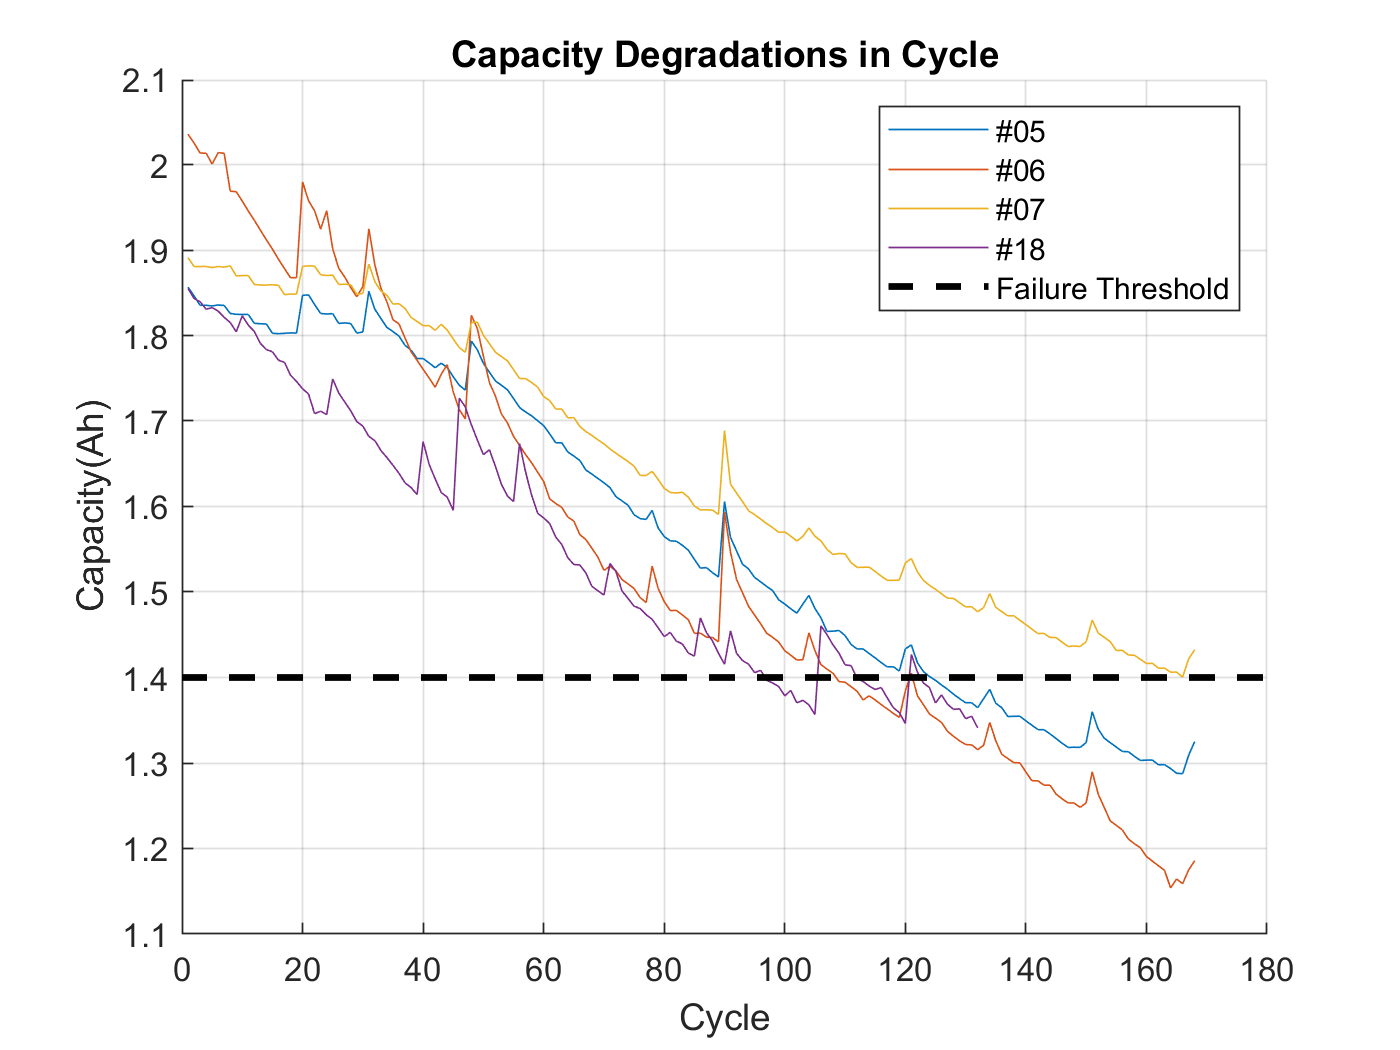

figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(cap05), hold on, plot(cap06), plot(cap07), plot(cap18); plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on, legend( '#05',                '#06',       '#07',       '#18','Failure Threshold')

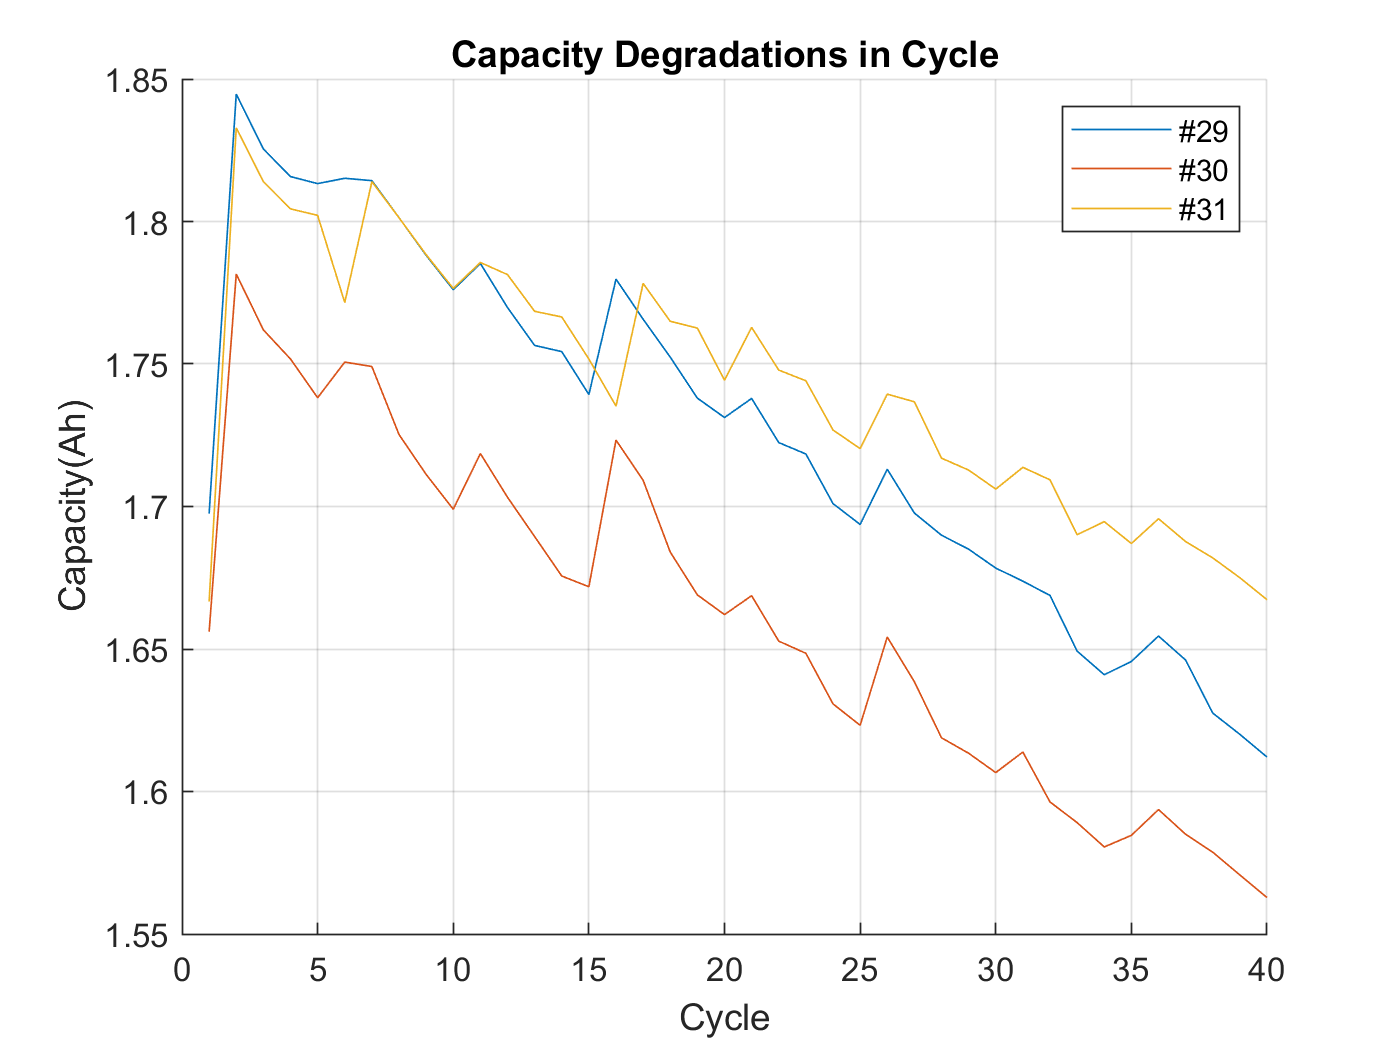


figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(cap29), hold on, plot(cap30), plot(cap31)
hold off, grid on, legend( '#29',                '#30',       '#31')

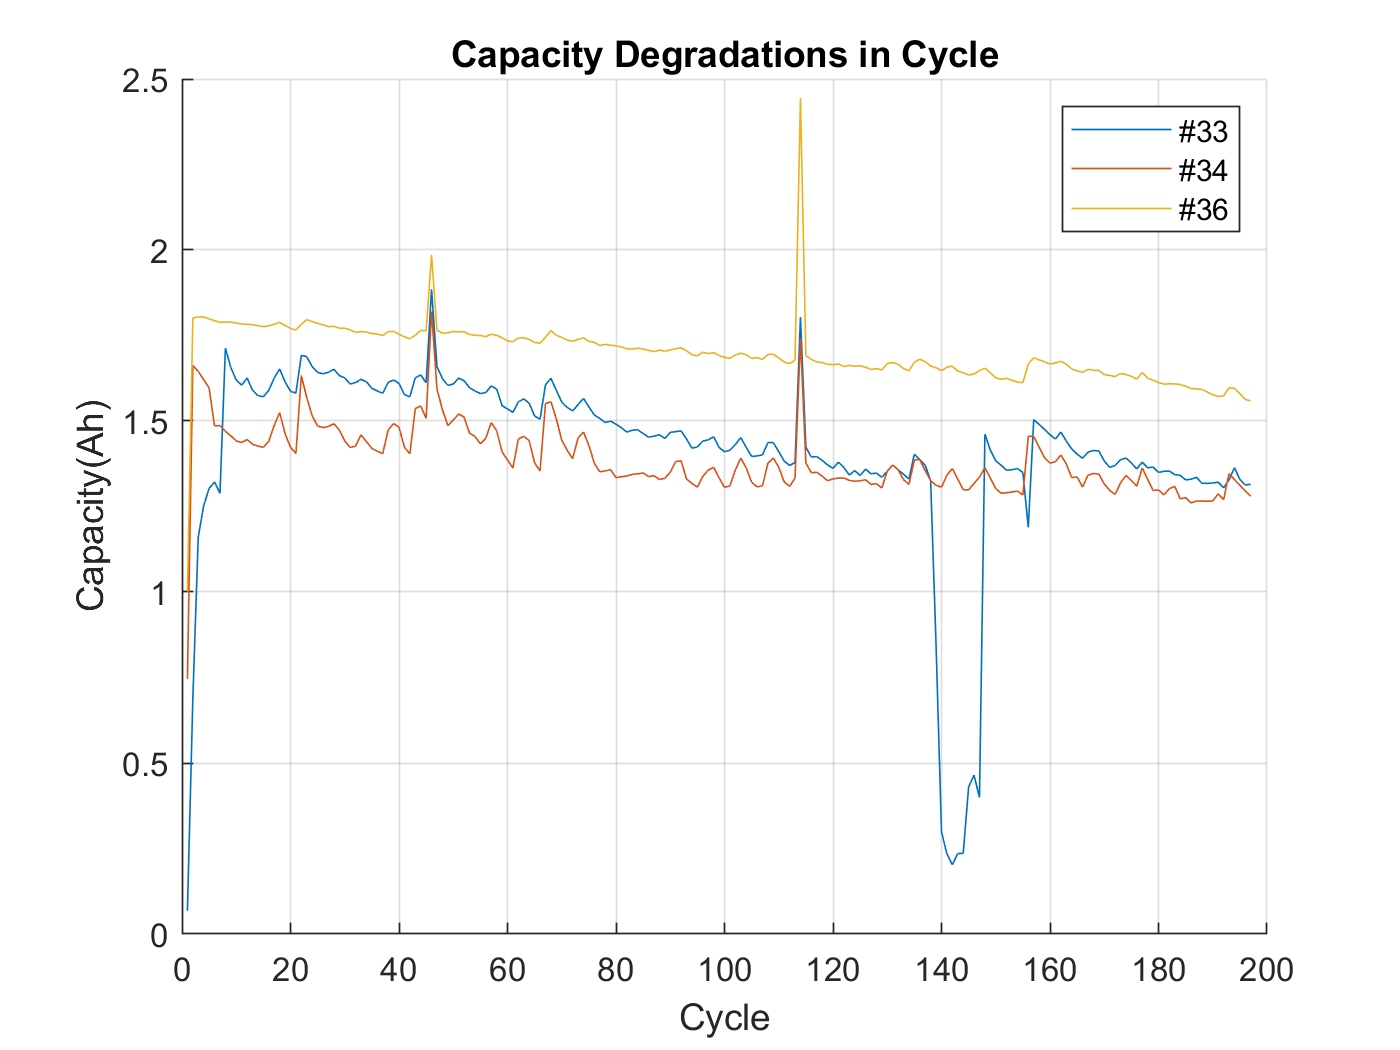


figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(cap33), hold on, plot(cap34), plot(cap36) 
hold off, grid on, legend( '#33',                '#34',       '#36')

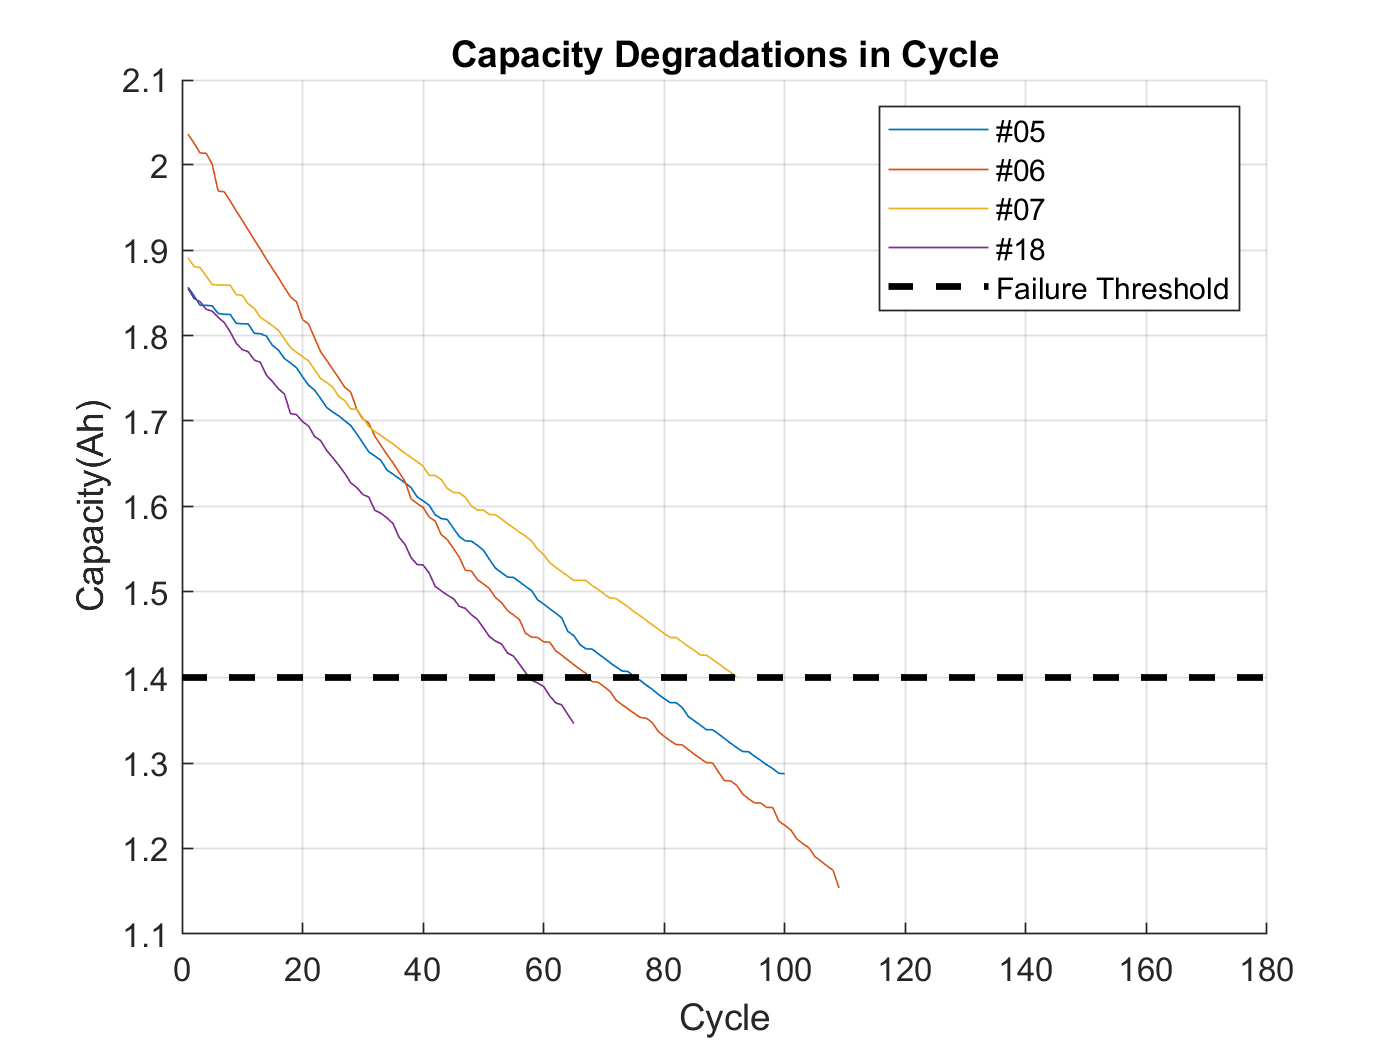

figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(capacity05), plot(capacity06), plot(capacity07), plot(capacity18); plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on, legend( '#05',                 '#06',            '#07',            '#18','Failure Threshold')

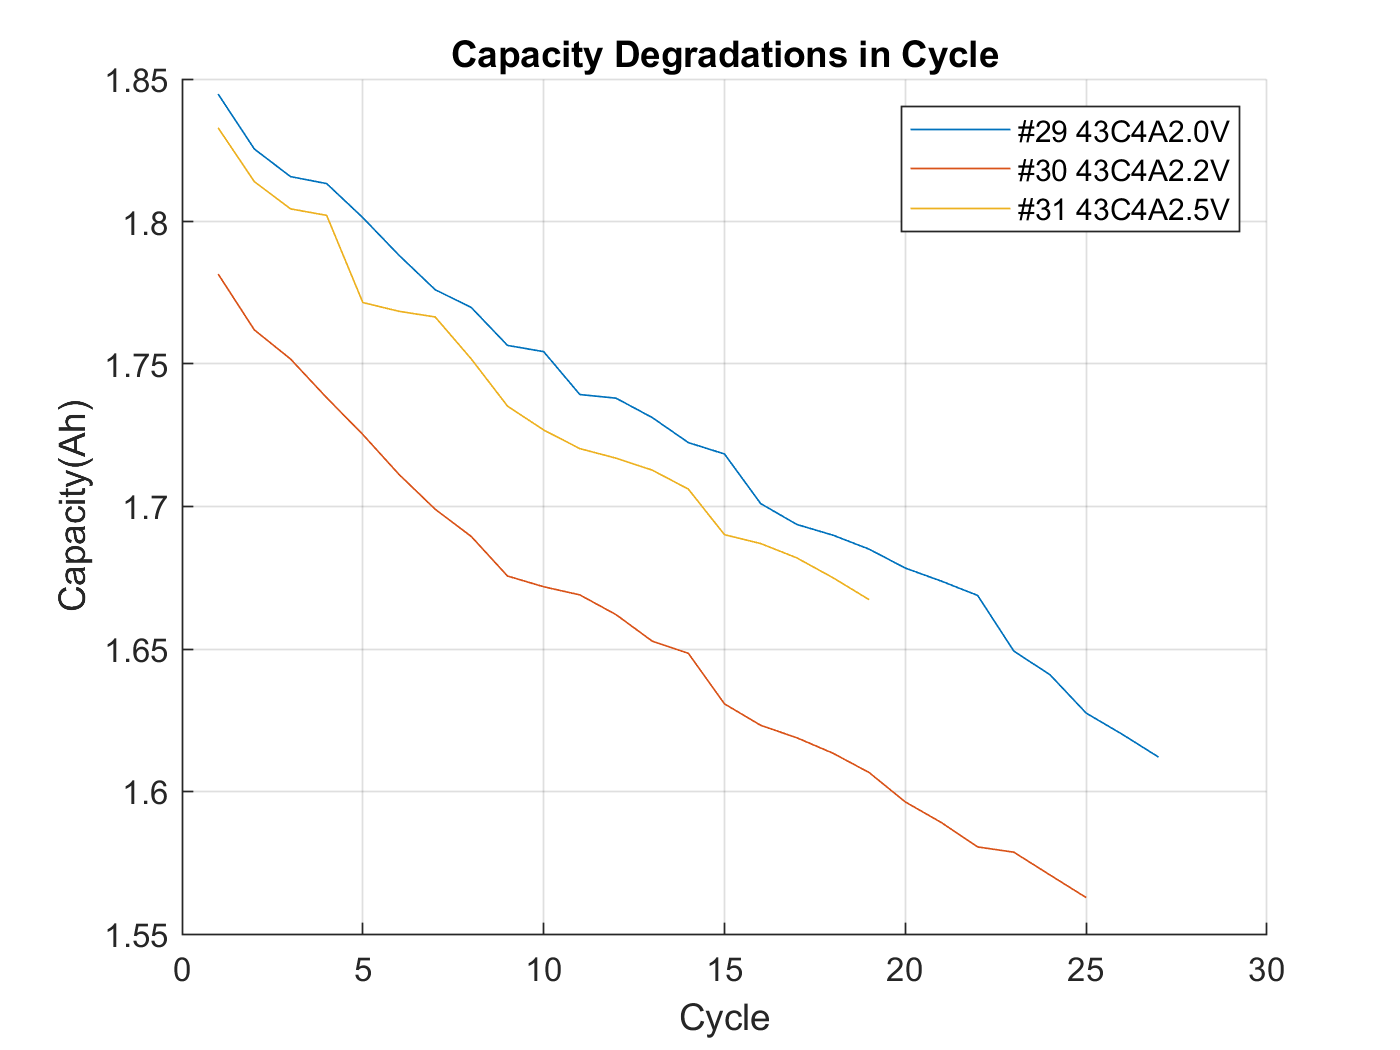


figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(capacity29), plot(capacity30), plot(capacity31)
hold off, grid on, legend( '#29 43C4A2.0V','#30 43C4A2.2V','#31 43C4A2.5V')

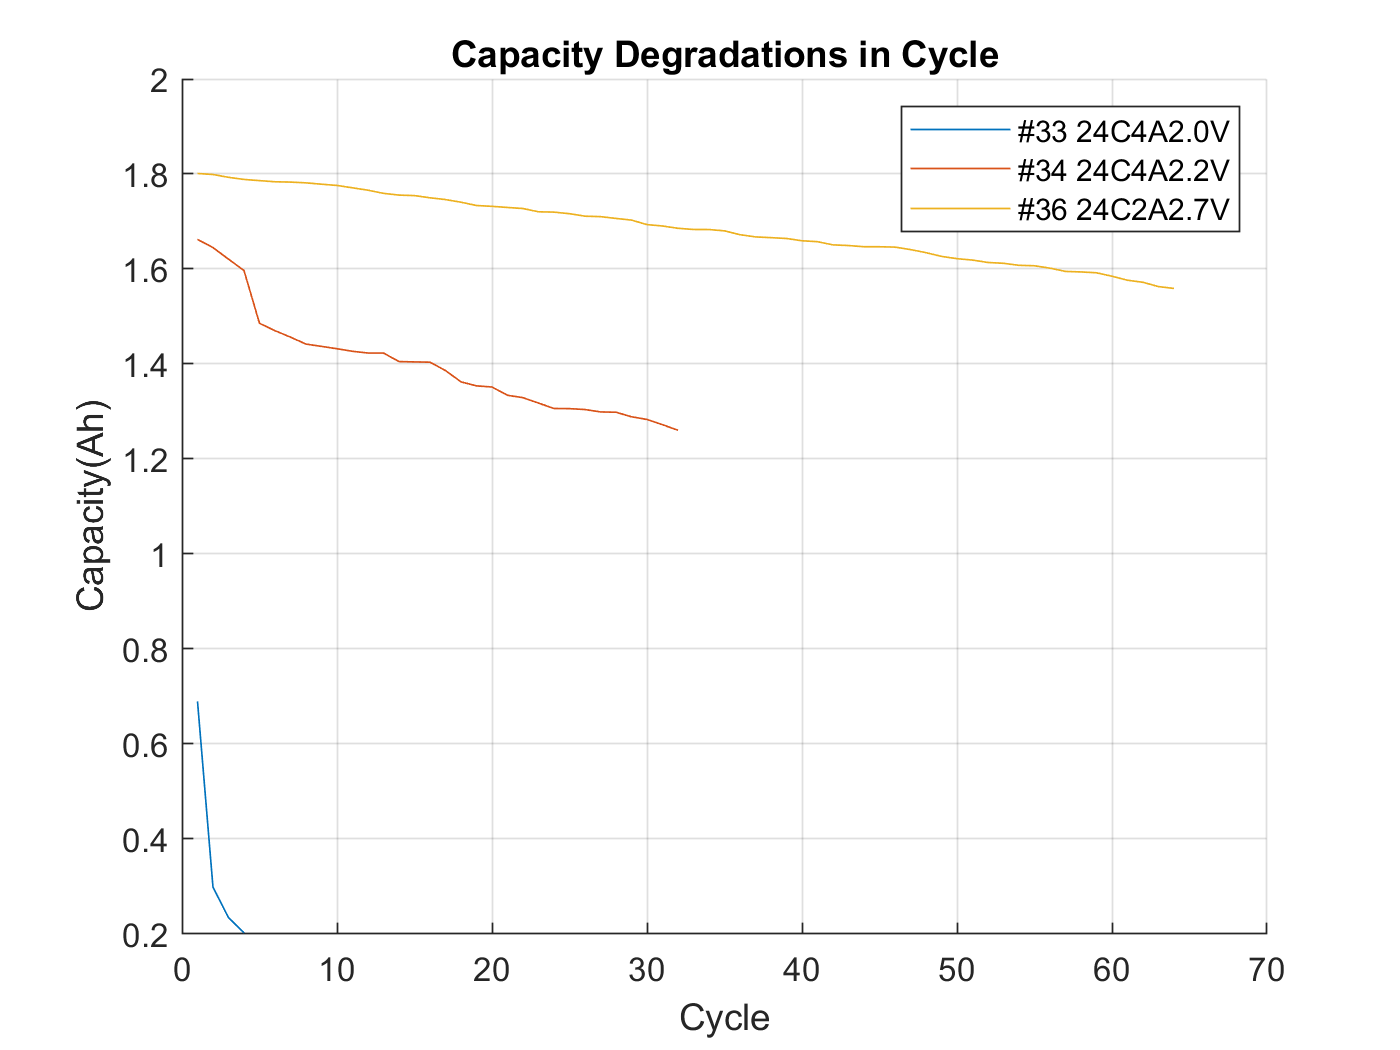


figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(capacity33), plot(capacity34), plot(capacity36) 
hold off, grid on, legend( '#33 24C4A2.0V','#34 24C4A2.2V','#36 24C2A2.7V')

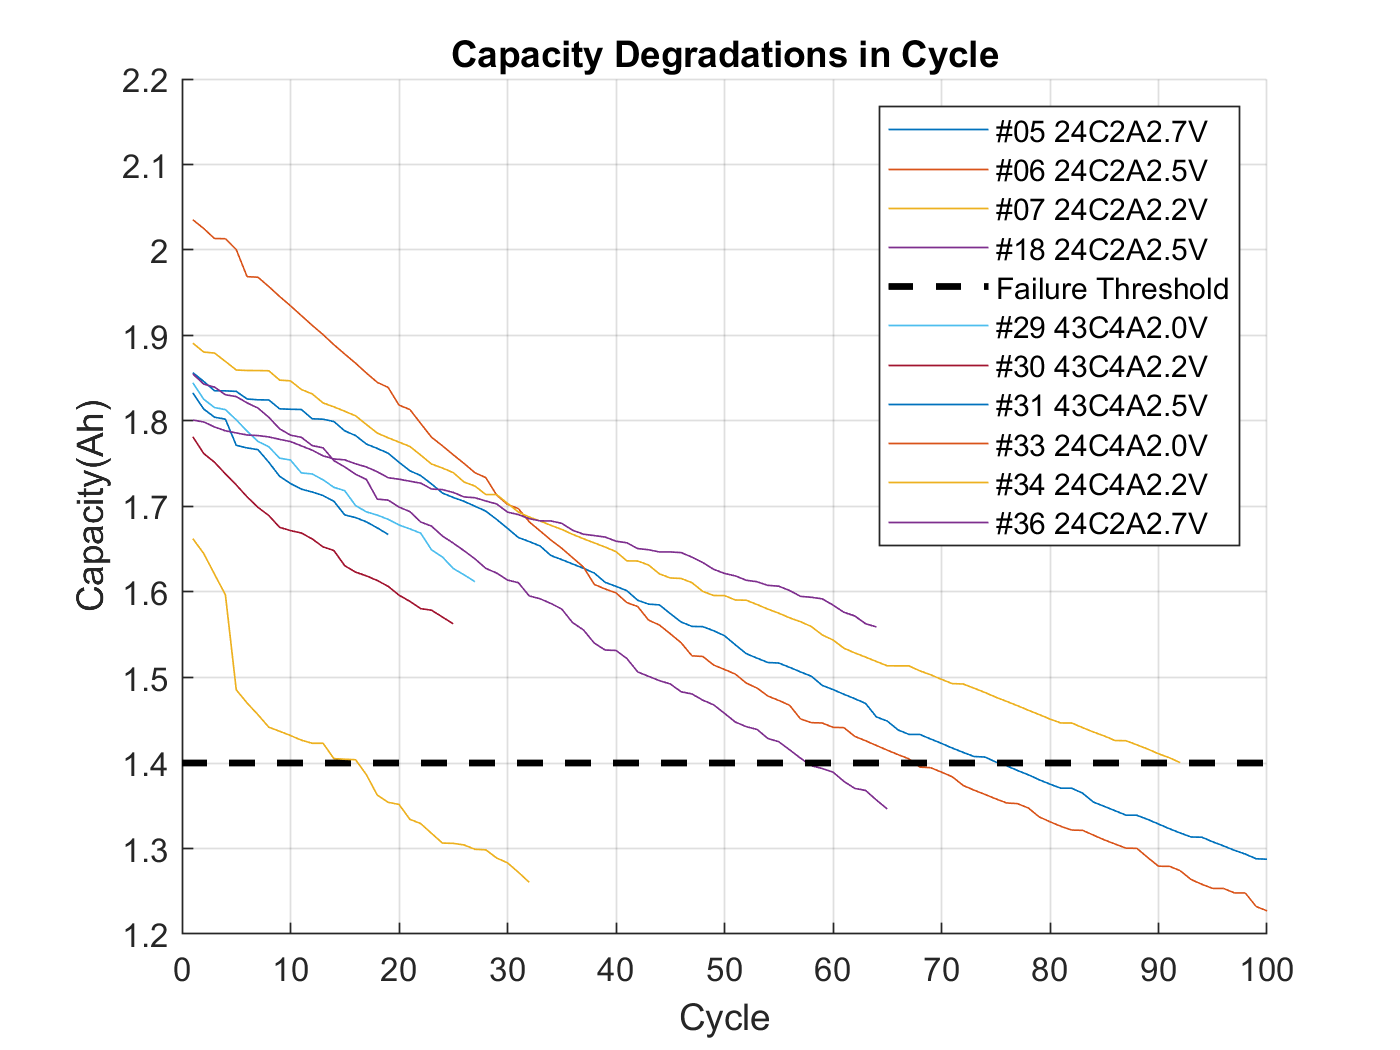

figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(capacity05), plot(capacity06), plot(capacity07), plot(capacity18); plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2),plot(capacity29), plot(capacity30), plot(capacity31),plot(capacity33), plot(capacity34), plot(capacity36) 
hold off, grid on, legend('#05 24C2A2.7V','#06 24C2A2.5V', '#07 24C2A2.2V','#18 24C2A2.5V','Failure Threshold','#29 43C4A2.0V','#30 43C4A2.2V','#31 43C4A2.5V','#33 24C4A2.0V','#34 24C4A2.2V','#36 24C2A2.7V')
ylim([1.2 2.2]), xlim([0,100])

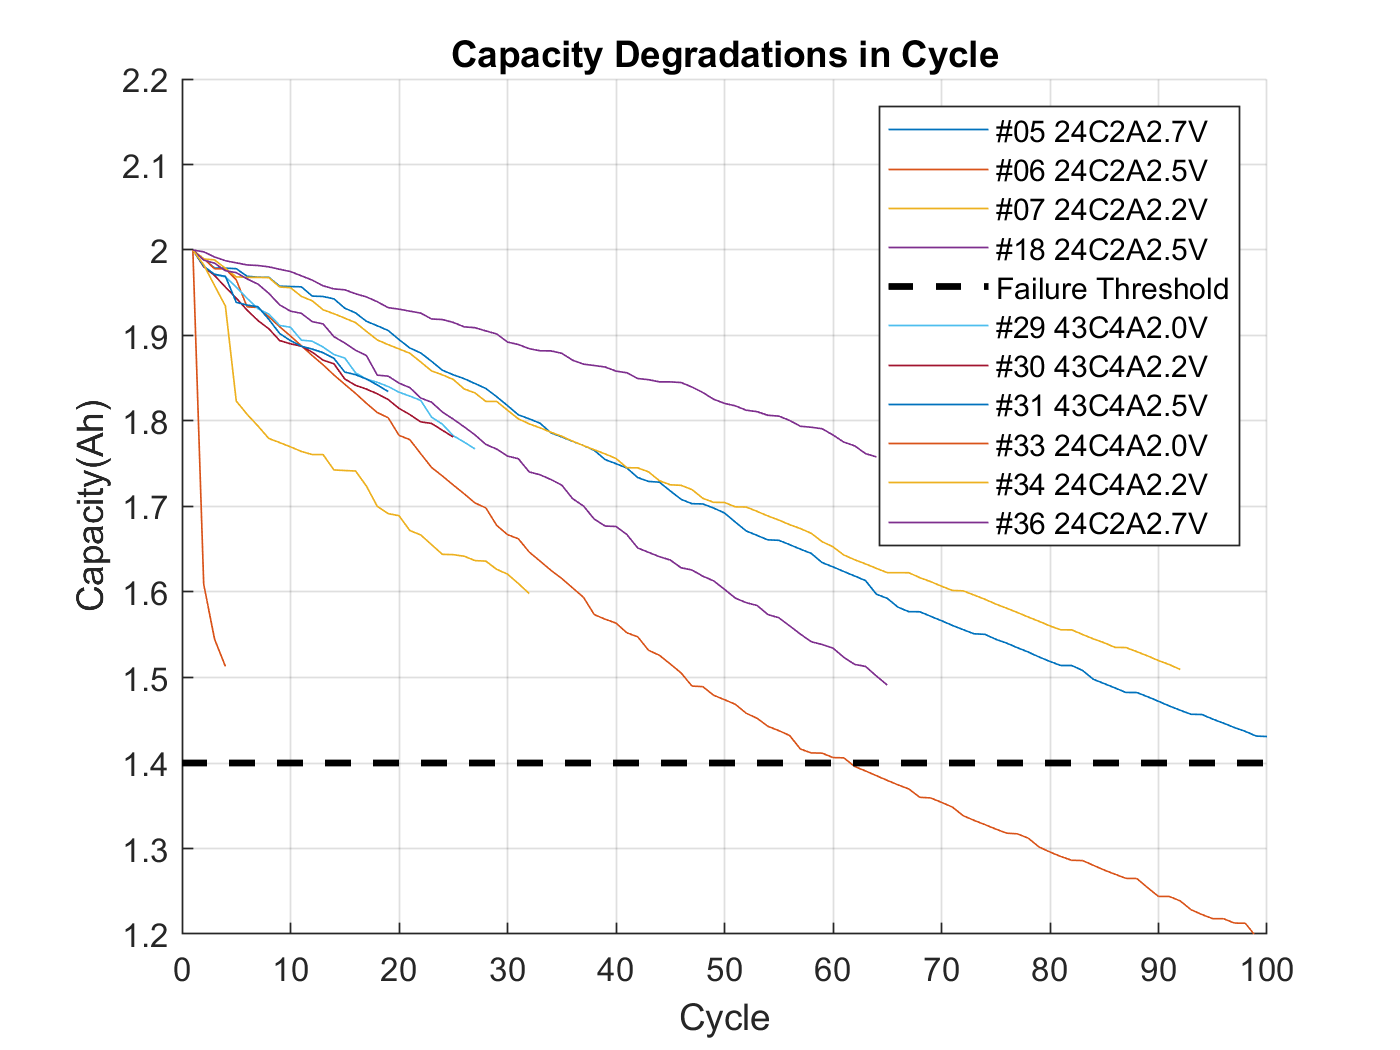

figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(capacityNorm05), plot(capacityNorm06), plot(capacityNorm07), plot(capacityNorm18); plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2),plot(capacityNorm29), plot(capacityNorm30), plot(capacityNorm31),plot(capacityNorm33), plot(capacityNorm34), plot(capacityNorm36) 
hold off, grid on, legend('#05 24C2A2.7V','#06 24C2A2.5V', '#07 24C2A2.2V','#18 24C2A2.5V','Failure Threshold','#29 43C4A2.0V','#30 43C4A2.2V','#31 43C4A2.5V','#33 24C4A2.0V','#34 24C4A2.2V','#36 24C2A2.7V')
ylim([1.2 2.2]), xlim([0,100])

figure,hold on,xlabel Cycle, ylabel Capacity(Ah),title('cTempMax in Cycle')
plot(cTempMax05),plot(cTempMax06),plot(cTempMax07),plot(cTempMax18),plot(cTempMax36)
hold off, grid on, legend('#05 24C2A2.7V','#06 24C2A2.5V', '#07 24C2A2.2V','#18 24C2A2.5V','#36 24C2A2.7V')

figure,hold on,xlabel Cycle, ylabel Capacity(Ah),title('dTempMax in Cycle')
plot(dTempMax05),plot(dTempMax06),plot(dTempMax07),plot(dTempMax18),plot(dTempMax36)
hold off, grid on, legend('#05 24C2A2.7V','#06 24C2A2.5V', '#07 24C2A2.2V','#18 24C2A2.5V','#36 24C2A2.7V')


figure,hold on,xlabel Cycle, ylabel Capacity(Ah),title('cCCEndTimeSec in Cycle')
plot(cCcEndTimeSec05),plot(cCcEndTimeSec06),plot(cCcEndTimeSec07),plot(cCcEndTimeSec18),plot(cCcEndTimeSec36)
hold off, grid on, legend('#05 24C2A2.7V','#06 24C2A2.5V', '#07 24C2A2.2V','#18 24C2A2.5V','#36 24C2A2.7V')


figure,hold on,xlabel Cycle, ylabel Capacity(Ah),title('dCcEndTimeSec in Cycle')
plot(dCcEndTimeSec05),plot(dCcEndTimeSec06),plot(dCcEndTimeSec07),plot(dCcEndTimeSec18),plot(dCcEndTimeSec36)
hold off, grid on, legend('#05 24C2A2.7V','#06 24C2A2.5V', '#07 24C2A2.2V','#18 24C2A2.5V','#36 24C2A2.7V')


figure,hold on,xlabel Cycle, ylabel Capacity(Ah),title('ohm in Cycle')
plot(ohm05),plot(ohm06),plot(ohm07),plot(ohm18),plot(ohm36)
hold off, grid on, legend('#05 24C2A2.7V','#06 24C2A2.5V', '#07 24C2A2.2V','#18 24C2A2.5V','#36 24C2A2.7V')

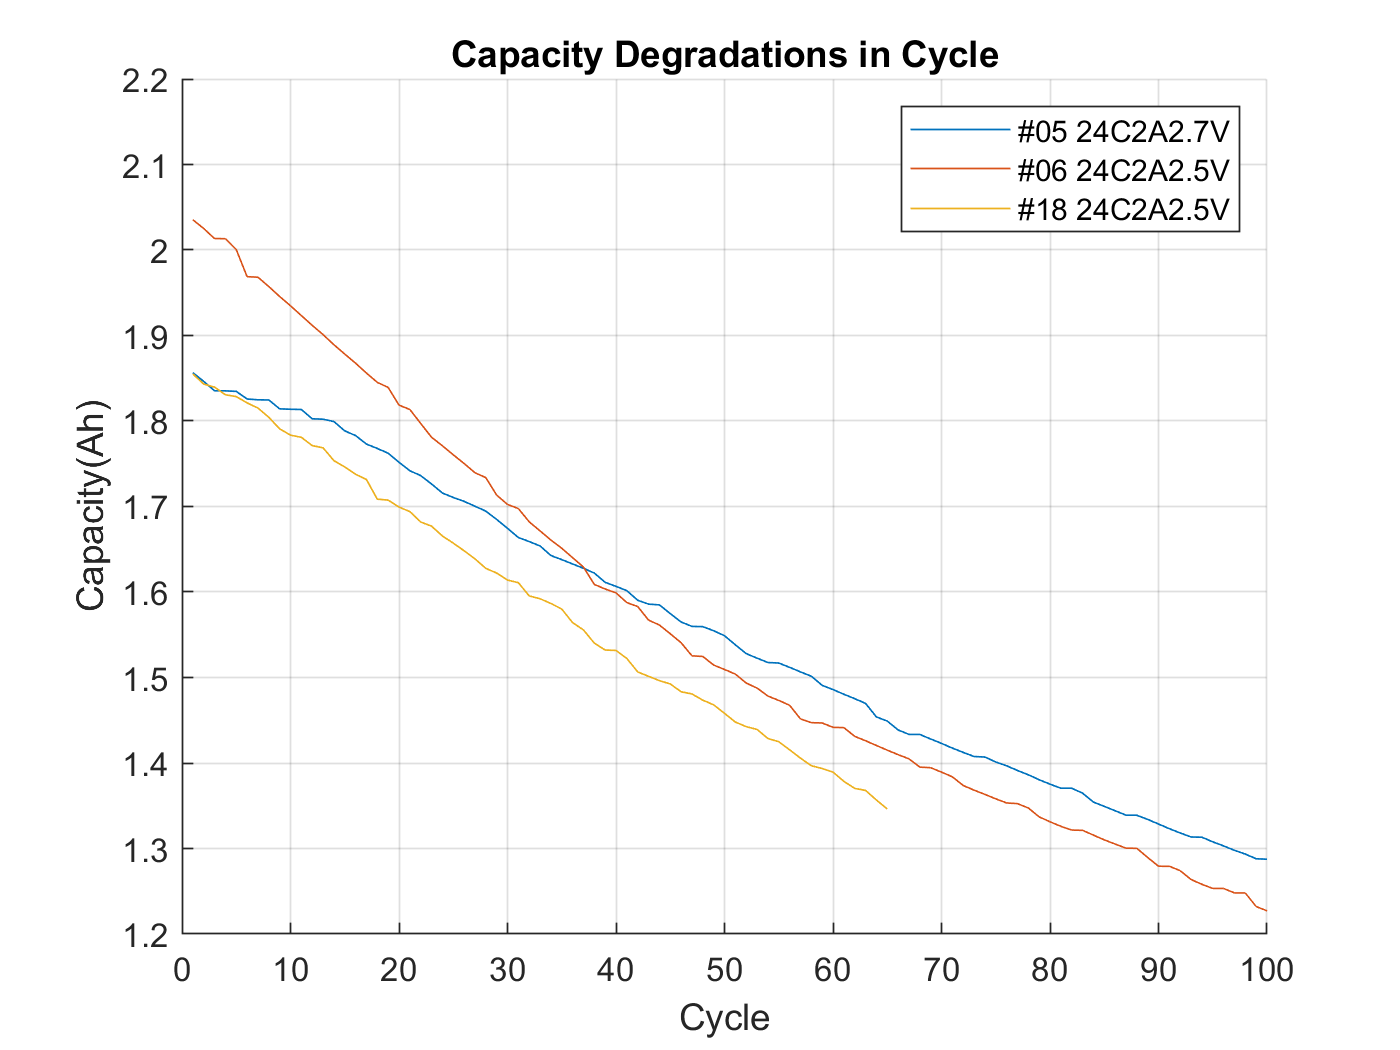


figure, hold on, xlabel Cycle, ylabel Capacity(Ah),title('Capacity Degradations in Cycle')
                     plot(capacity05), plot(capacity06),plot(capacity18)
hold off, grid on, legend('#05 24C2A2.7V','#06 24C2A2.5V','#18 24C2A2.5V')
ylim([1.2 2.2]), xlim([0,100])

%{
% gen
% 58 53
% new data set #01 / #02
result_05(58,1)
result_06(53,1)

% ignore rest time , maxTempDt 
result_05_06 = [ result_05(1:58,:) ; result_06(:,53:end) ];
result_06_05 = [ result_06(1:53,:) ; result_05(:,58:end) ];
result_05_06_all = [ result_05 ; result_06 ];
%}

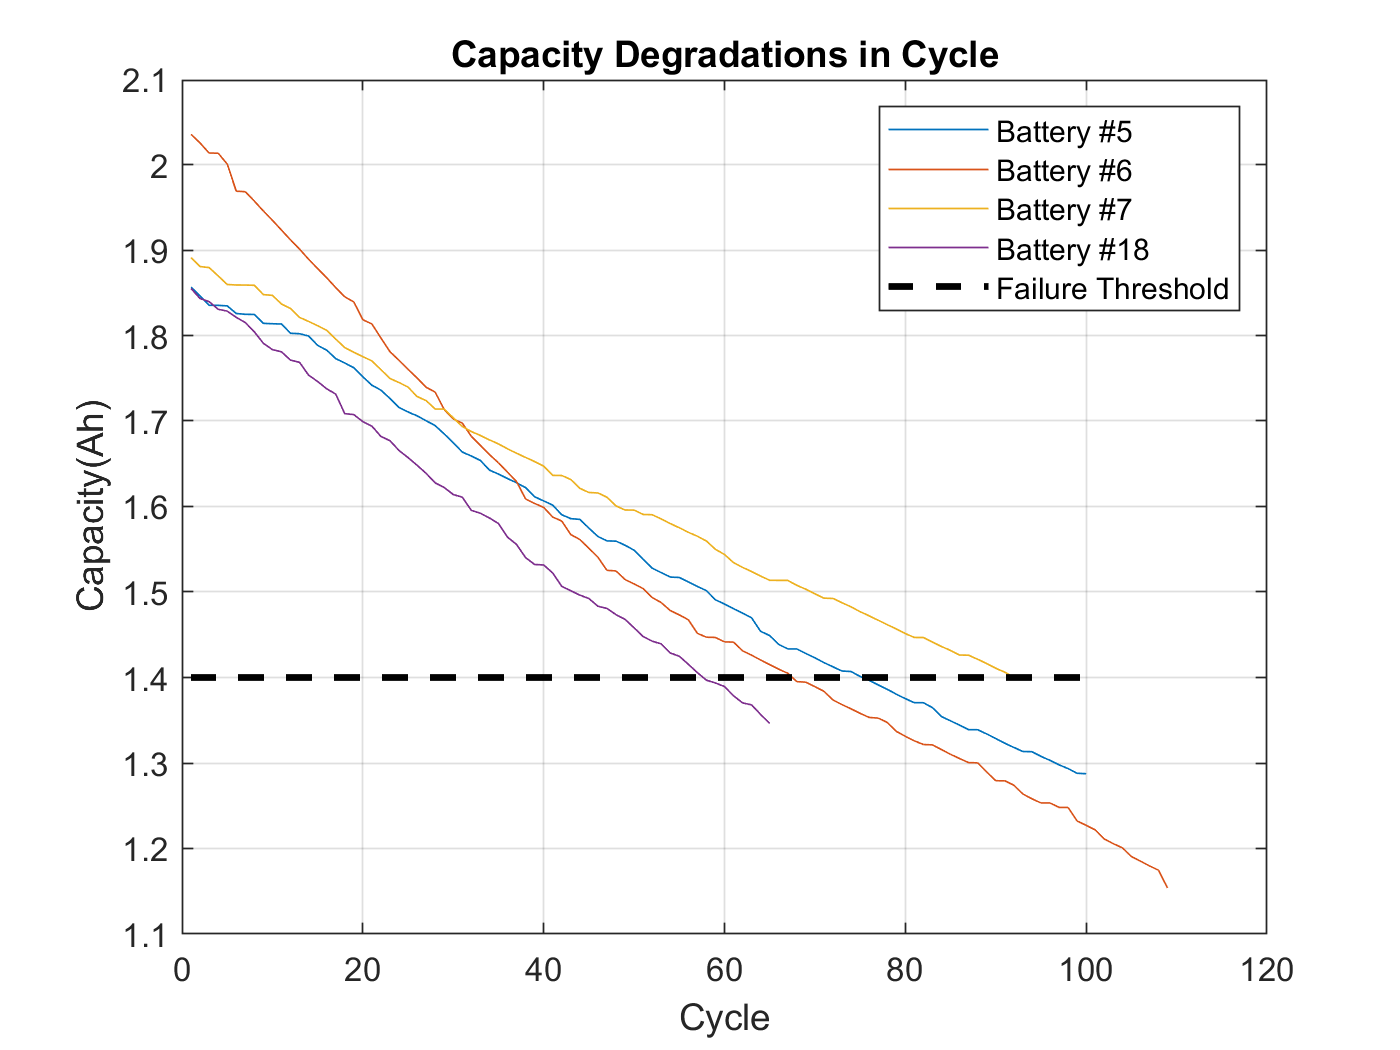

%% org graph - cycle
cycle_number = length(capacity05);

figure
plot(capacity05), hold on, plot(capacity06), plot(capacity07), plot(capacity18)
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Cycle')

% modify ohm   20 -> 30
result_05(1:30,ohmIdx) = nan;
result_06(1:30,ohmIdx) = nan;
% no gen
% 27 30
% new data set #01 / #02
result_05(27,1)

ans = 1.7003

result_06(30,1)

ans = 1.7024


% ignore rest time , maxTempDt 
result_05_06 = [ result_05(1:27,:) ; result_06(31:end,:) ]; % 30 -> 31
result_06_05 = [ result_06(1:30,:) ; result_05(27:end,:) ];
result_05_06_patten_change = [27 31];
result_06_05_patten_change = [30 27];

result_05_06_all = [ result_05 ; result_06 ];
capacity56 = result_05_06(:,1);
capacity65 = result_06_05(:,1);
capacity_all = result_05_06_all(:,1);


%% create vector / table
    
regression_vector_05 = [ ...
    result_05(:, cCcEndTimeSecIdx ) ...
    result_05(:, pattern_dVoltIdx ) ...
    result_05(:, capacityIdx ) ] ;

regression_vector_06 = [ ...
    result_06(:, cCcEndTimeSecIdx ) ...
    result_06(:, pattern_dVoltIdx ) ...
    result_06(:, capacityIdx ) ] ;


regression_vector_05_06_all = [ ...
    result_05_06_all(:, cCcEndTimeSecIdx ) ...
    result_05_06_all(:, pattern_dVoltIdx ) ...
    result_05_06_all(:, capacityIdx ) ] ;

regression_vector_05_06 = [ ...
    result_05_06(:, cCcEndTimeSecIdx ) ...
    result_05_06(:, pattern_dVoltIdx ) ...
    result_05_06(:, capacityIdx ) ] ;

regression_vector_06_05 = [ ...
    result_06_05(:, cCcEndTimeSecIdx ) ...
    result_06_05(:, pattern_dVoltIdx ) ...
    result_06_05(:, capacityIdx ) ] ;

% works
regression_table_05 = array2table(regression_vector_05,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_06 = array2table(regression_vector_06,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_05_06 = array2table(regression_vector_05_06,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_06_05 = array2table(regression_vector_06_05,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_05_06_all = array2table(regression_vector_05_06_all,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

    
% https://kr.mathworks.com/help/matlab/ref/cell2table.html    
% works
%{
regression_table_5 = array2table(regression_vector_05,...
    'VariableNames',{'cCcEndTimeSec','capacity'});

regression_table_6 = array2table(regression_vector_06,...
    'VariableNames',{'cCcEndTimeSec','capacity'});
%}


## corellaton

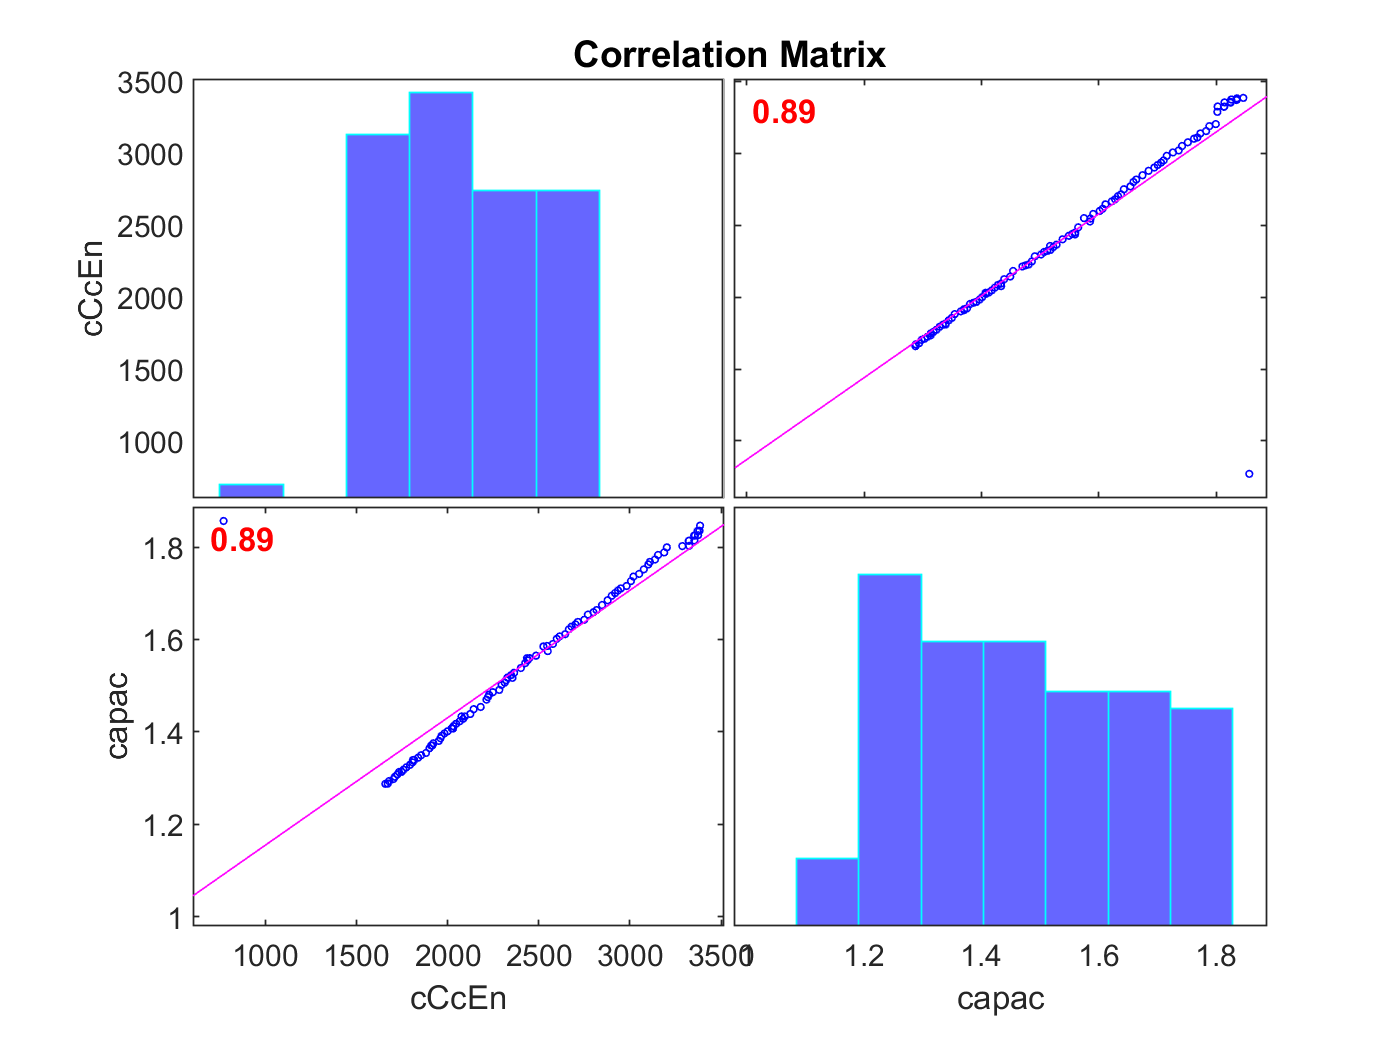


% error after adding pattern_dVolt
figure
corrplot(regression_vector_05(:,[1 3]),'type','Pearson','testR','on','varNames',{'cCcEndTimeSec','capacity'})

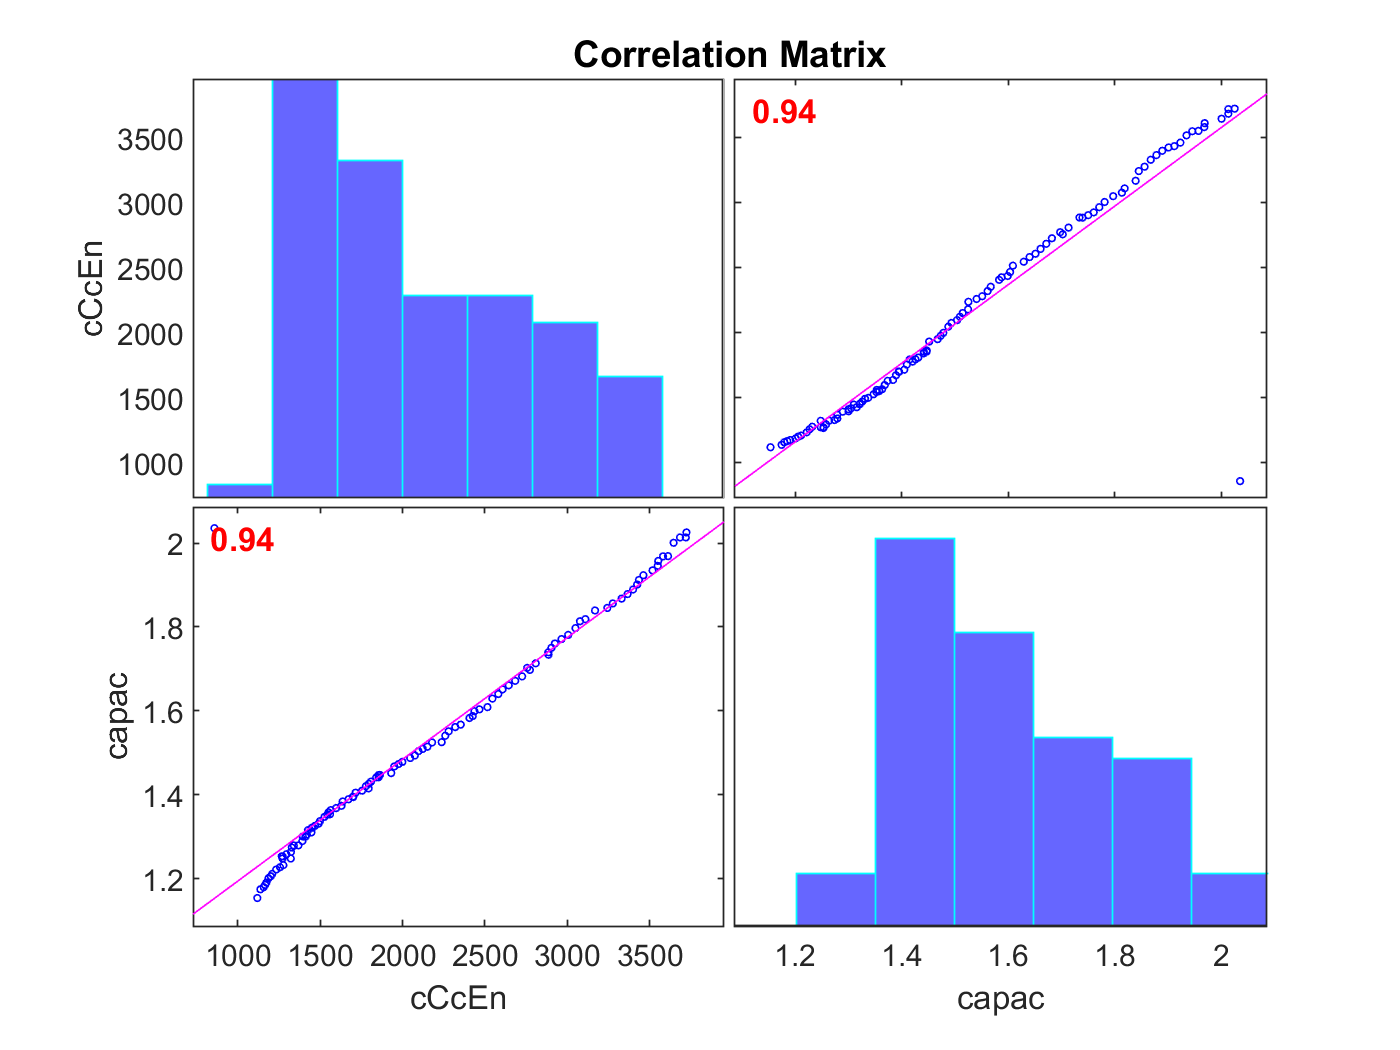

figure
corrplot(regression_vector_06(:,[1 3]),'type','Pearson','testR','on','varNames',{'cCcEndTimeSec','capacity'})

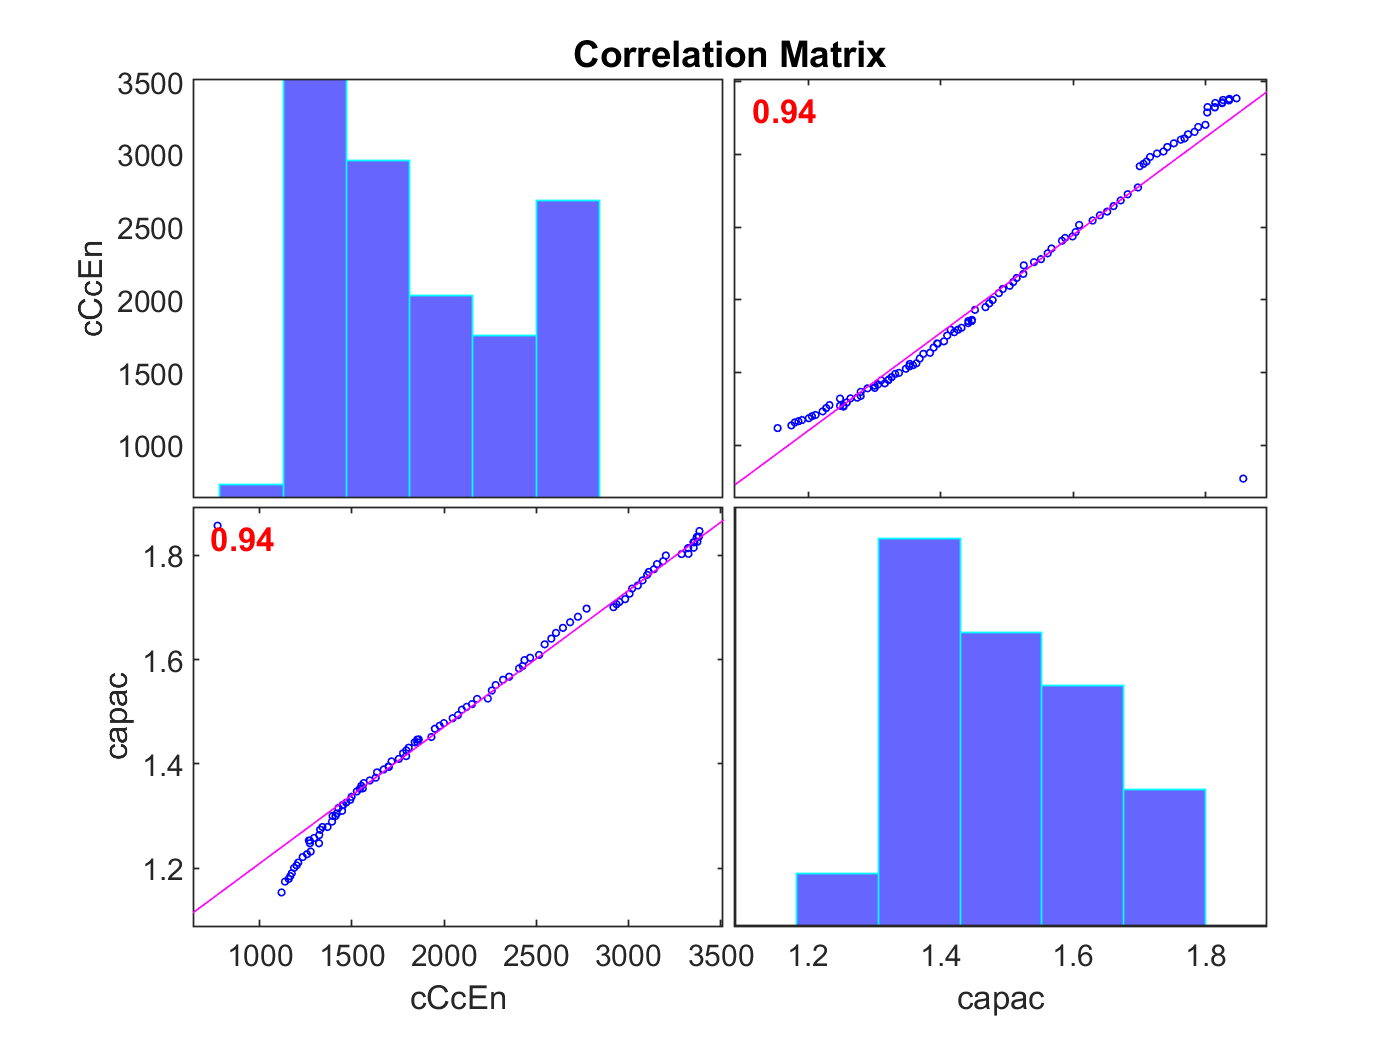

figure
corrplot(regression_vector_05_06(:,[1 3]),'type','Pearson','testR','on','varNames',{'cCcEndTimeSec','capacity'})

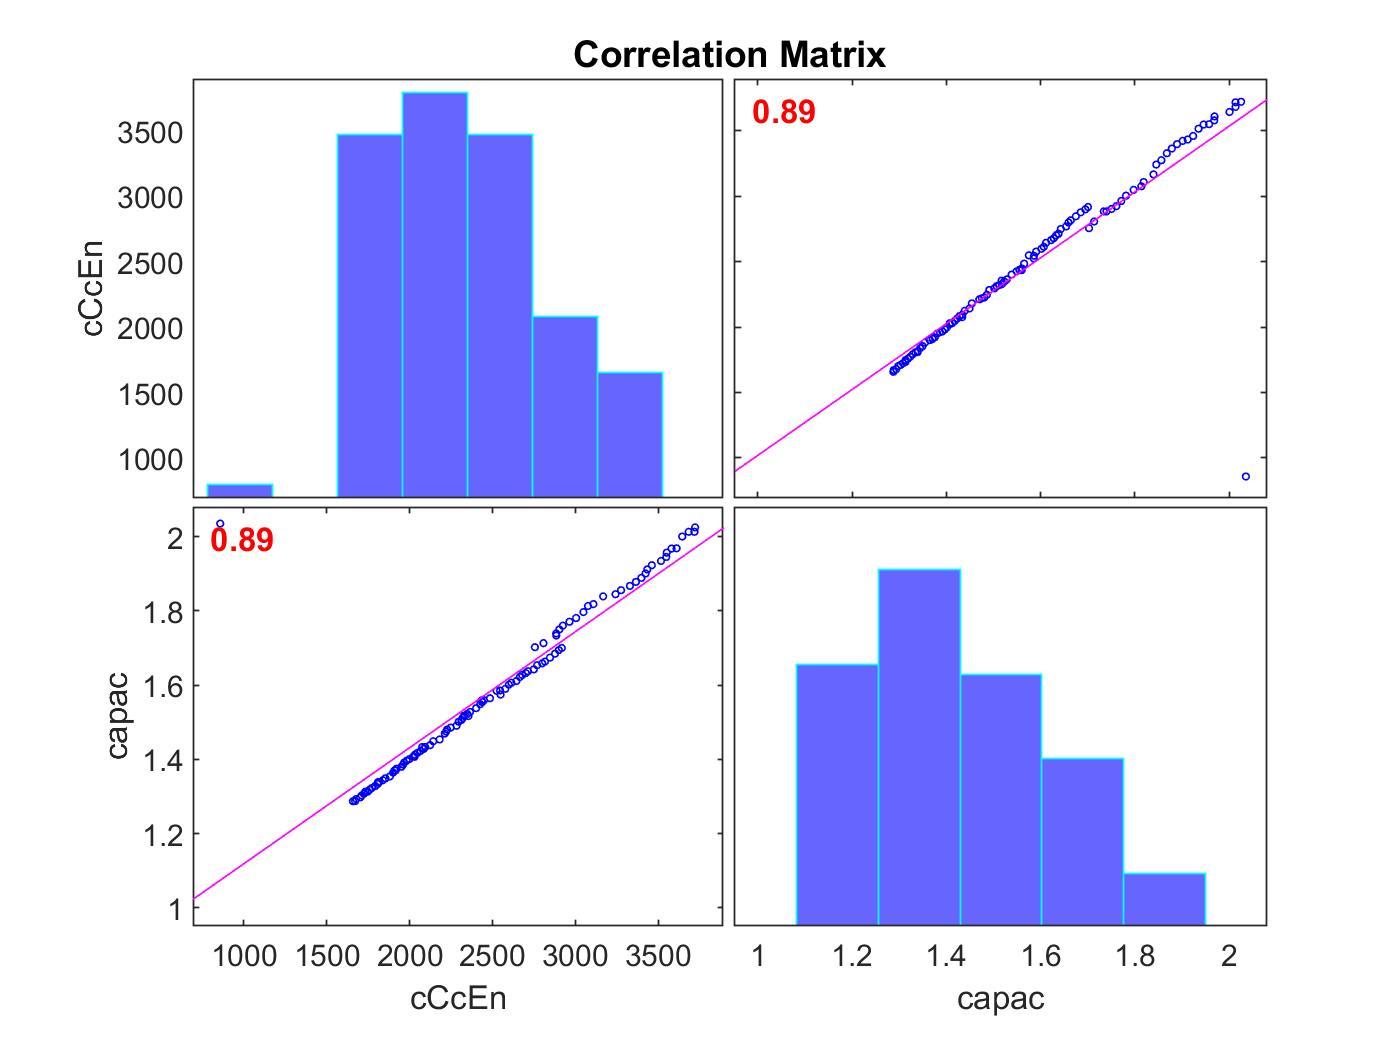

figure
corrplot(regression_vector_06_05(:,[1 3]),'type','Pearson','testR','on','varNames',{'cCcEndTimeSec','capacity'})

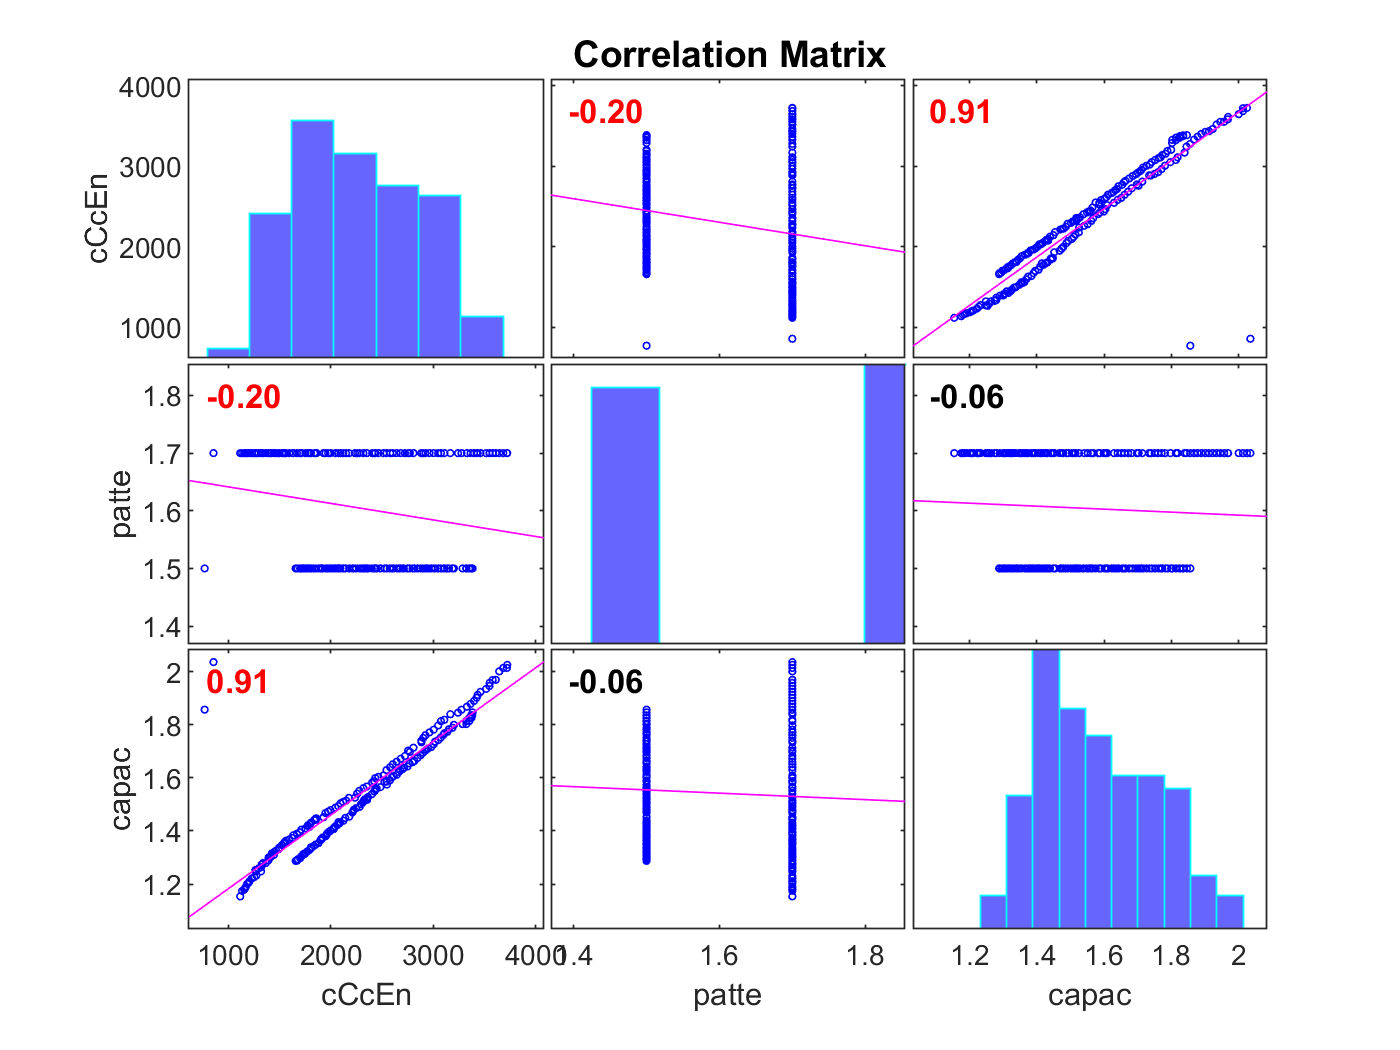

figure
corrplot(regression_vector_05_06_all,'type','Pearson','testR','on','varNames',{'cCcEndTimeSec','pattern_dVolt','capacity'})

% https://people.duke.edu/~rnau/arimrule.htm
% https://github.com/KevinChngJY/timeseriesinmatlab

% https://kr.mathworks.com/help/econ/specify-ar-models.html
X5 = regression_vector_05(:,1);
X5 = X5./1200 ; % sec to hour
Y5 = regression_vector_05(:,3);
U5 = regression_vector_05(:,2);

Y6 = regression_vector_06(:,3);
U6 = regression_vector_06(:,2);

Y56 = regression_vector_05_06(:,3);
U56 = regression_vector_05_06(:,2);

Y65 = regression_vector_06_05(:,3);
U65 = regression_vector_06_05(:,2);

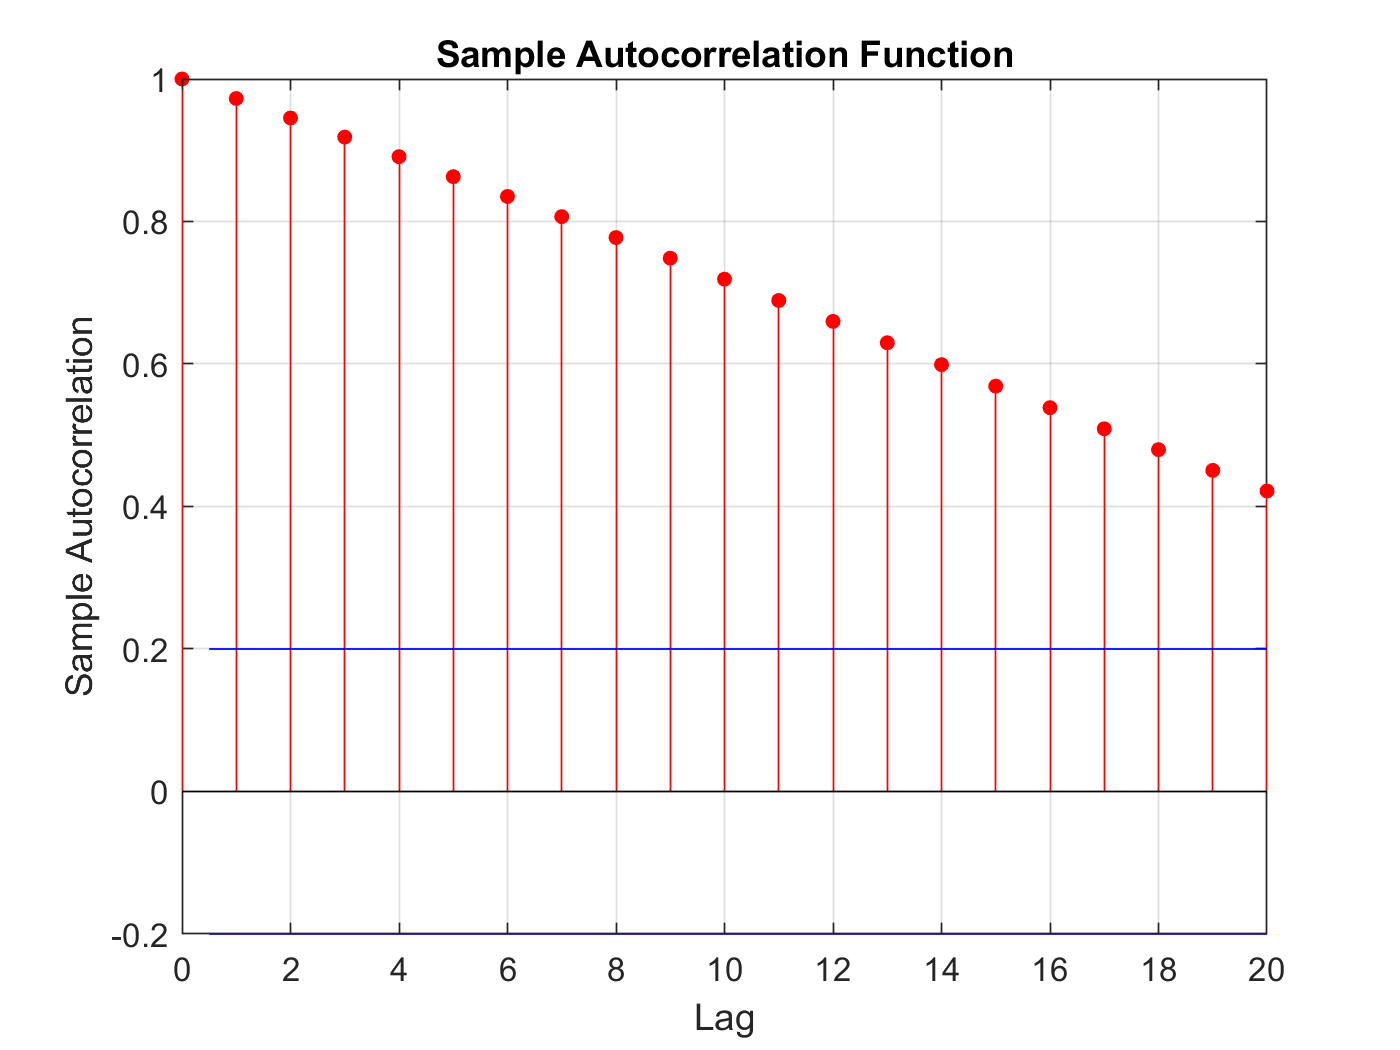


figure
autocorr(Y5)

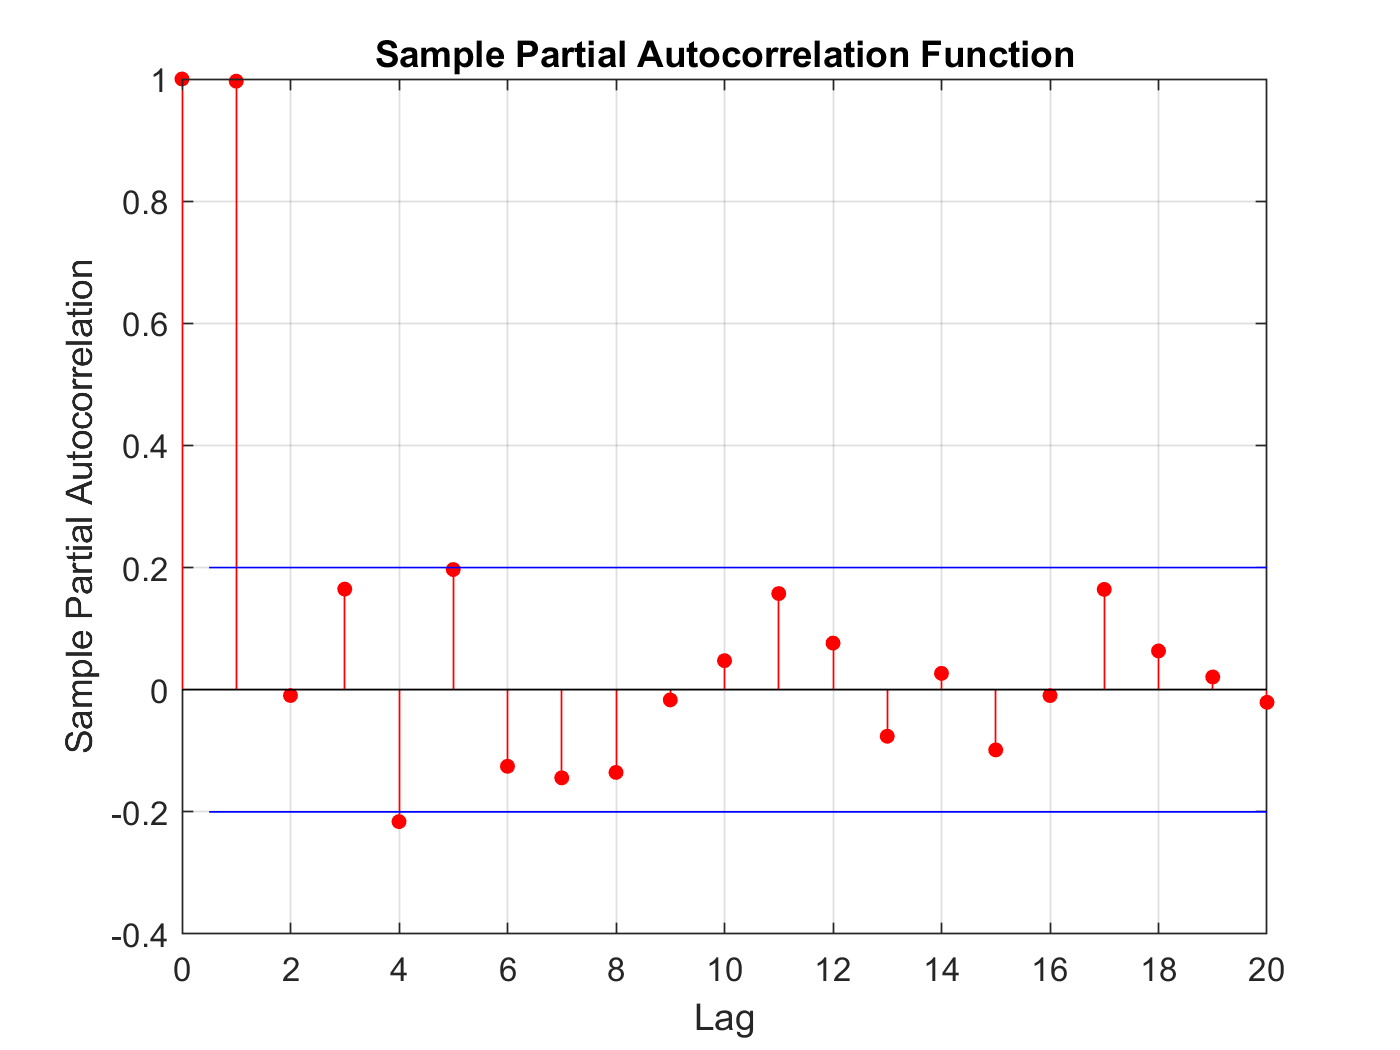

figure
parcorr(Y5)


acf = autocorr(Y5,'NumLags',15)

acf =     1.0000
    0.9726
    0.9453
    0.9185
    0.8910
    0.8629
    0.8352
    0.8068
    0.7775
    0.7486


pacf = parcorr(Y5,'NumLags',15)

pacf =     1.0000
    0.9964
   -0.0095
    0.1648
   -0.2160
    0.1968
   -0.1254
   -0.1443
   -0.1354
   -0.0167


[length(acf) length(pacf)]

ans =     16    16


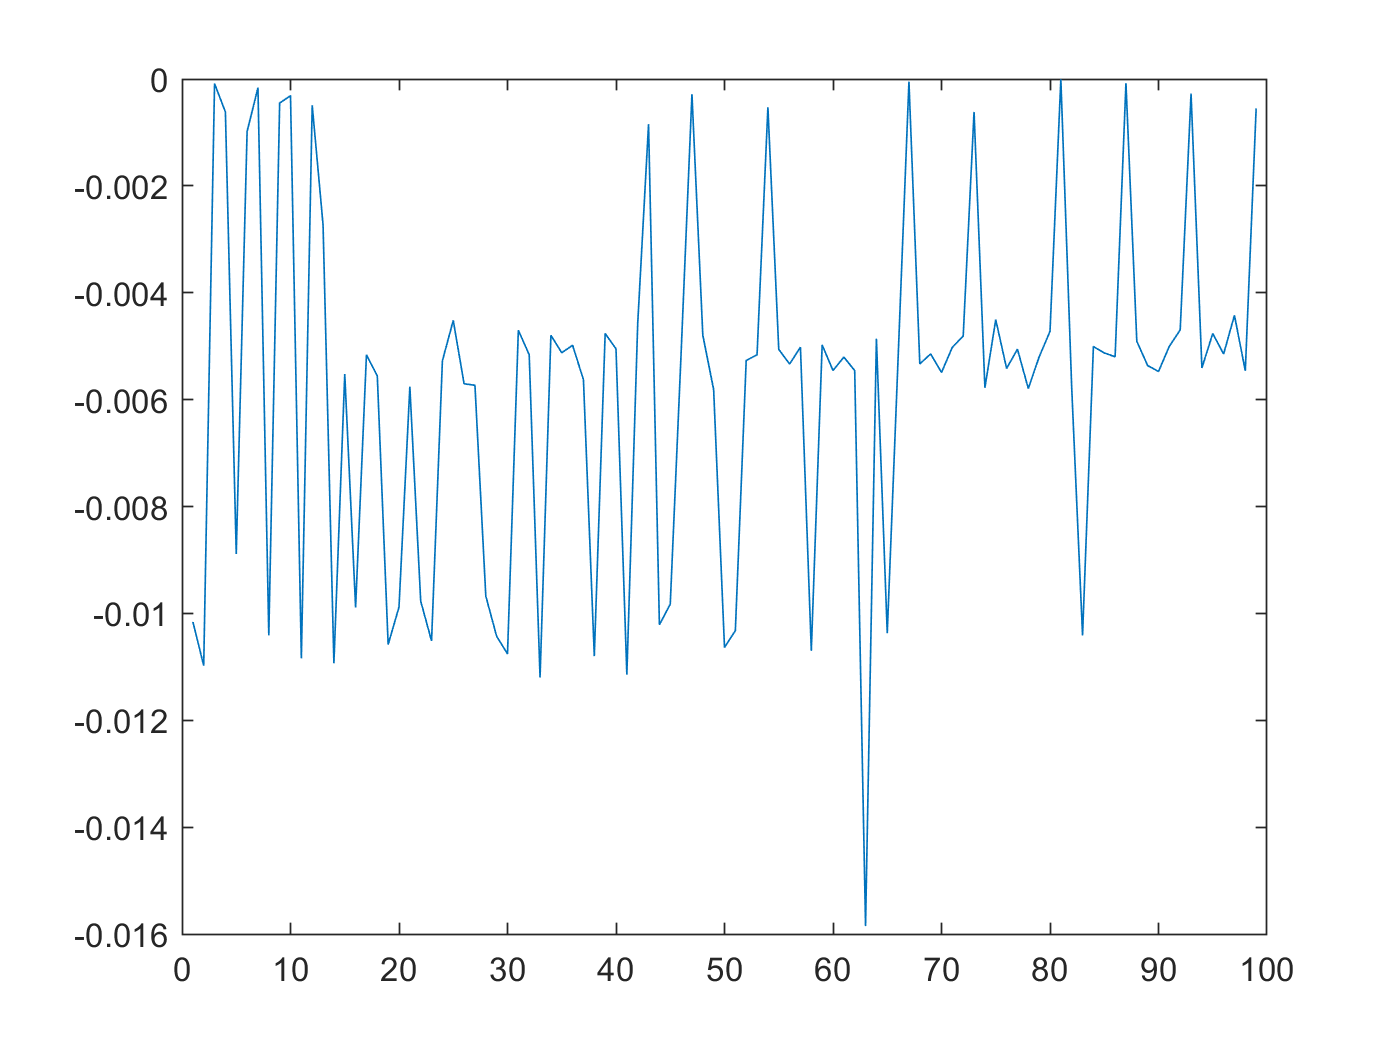


% https://kr.mathworks.com/help/econ/box-jenkins-differencing-vs-arima-estimation.html
%YDiff5 = Y5(2:end) - Y5(1:end-1);
YDiff5 = diff(Y5);

figure 
plot(YDiff5)

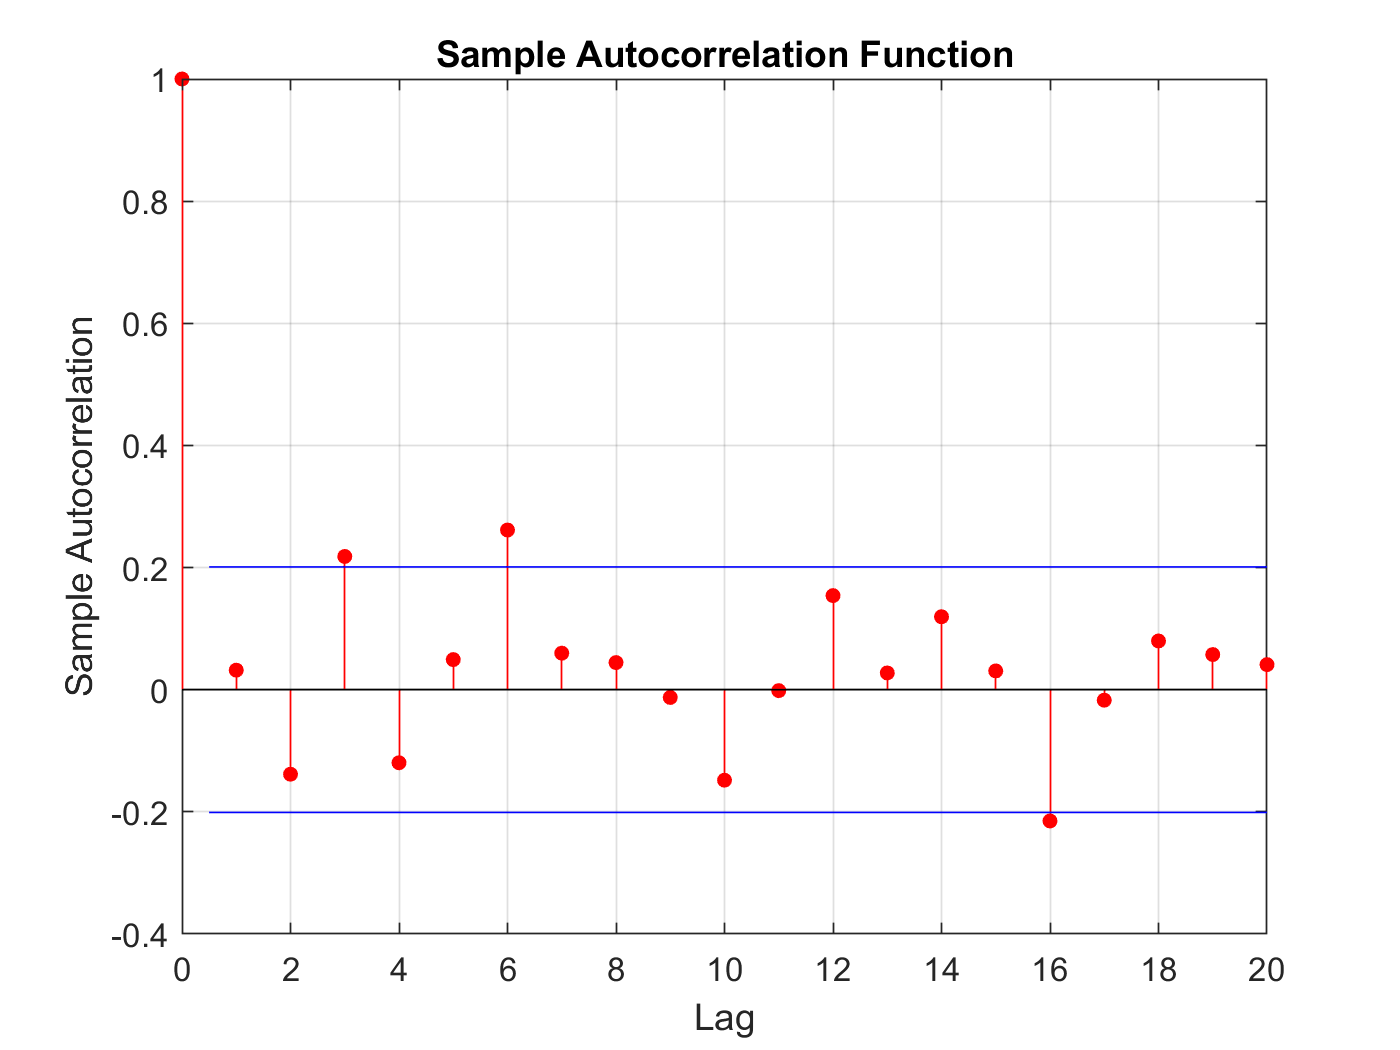

figure
autocorr(YDiff5)

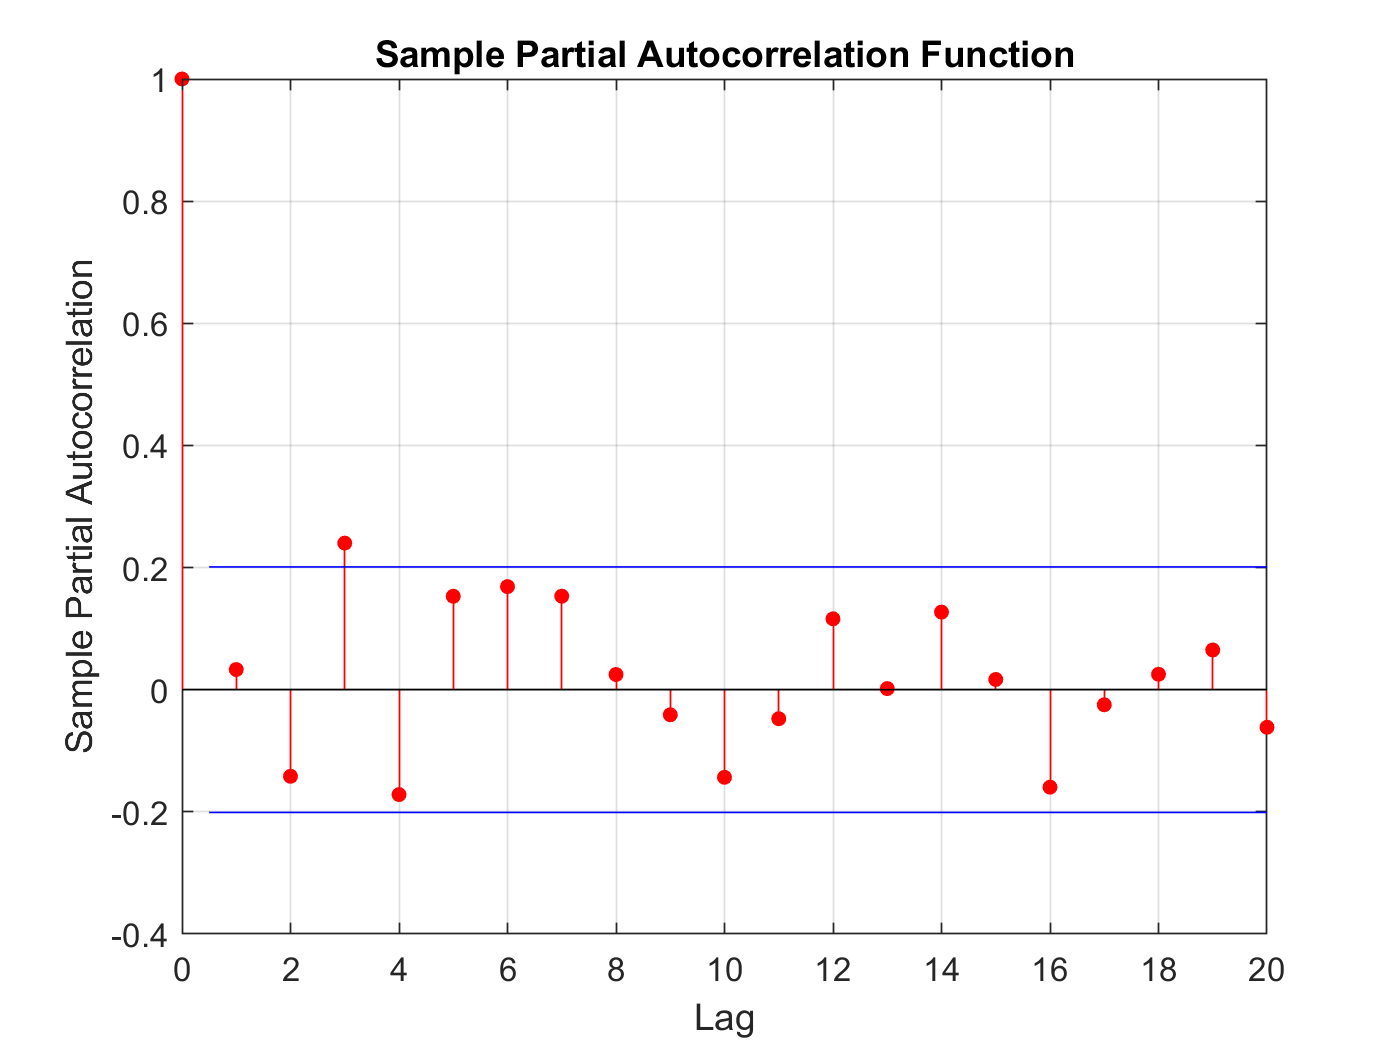

figure
parcorr(YDiff5)

learning_end_index = 27;
est_length = length(Y5) - learning_end_index;
end_index = length(Y5);

idxpre = 1:learning_end_index;
idxest = (learning_end_index+1):end_index;
% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl = arima(0,1,0);  % 0 1 0
%Mdl = arima(0,1,3);
EstMdl = estimate(Mdl,Y5(idxest),...
    'Y0',Y5(idxpre));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0056563     0.00039009         -14.5      1.2108e-47
    Variance    9.6256e-06     8.4775e-07        11.354      7.0643e-30



EstMdl

EstMdl =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: -0.00565627
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 9.62557e-06

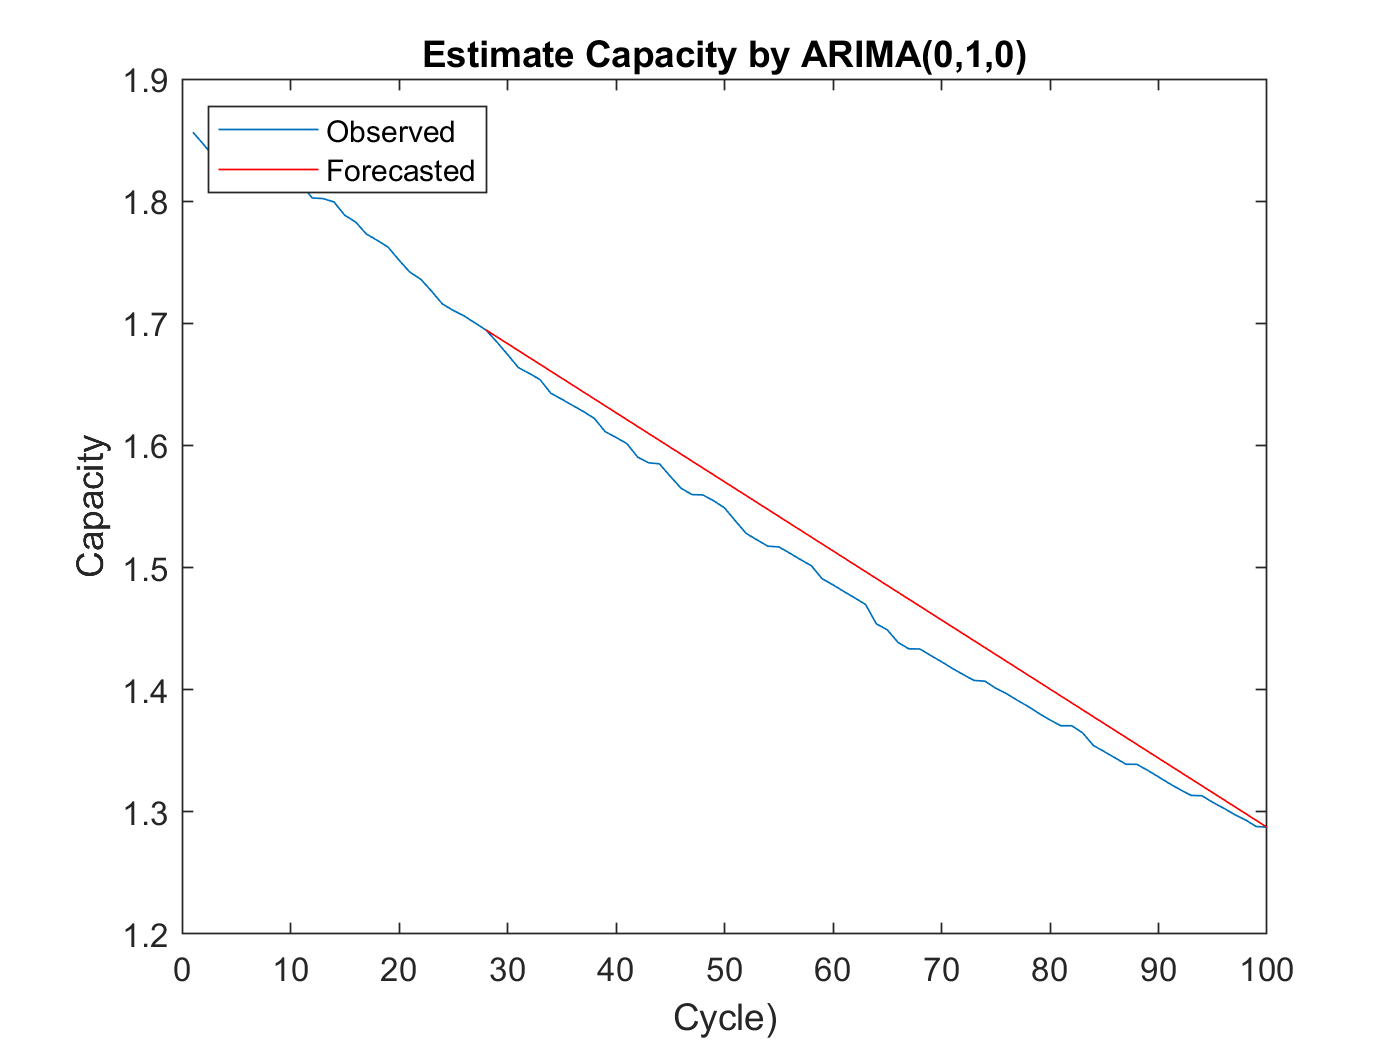


yf0 = Y5(idxpre(end - 1:end));
%yf0 = Y5(idxpre(1:end));

yf = forecast(EstMdl,est_length,yf0);
%Plot the first xxx observations and the forecasts.

figure
h1 = plot(Y5);
hold on
h2 = plot([(learning_end_index+1):end_index],yf,'r');
%h2 = plot([Y5(1:learning_end_index);yf])
legend([h1 h2],"Observed","Forecasted",...
	     'Location',"NorthWest")
title("Estimate Capacity by ARIMA(0,1,0)")
xlabel("Cycle)")
ylabel("Capacity")
hold off

% p,q => max 3 
% to avoid this message
% The error message “the non-seasonal autoregressive polynomial is unstable” 
% https://kr.mathworks.com/matlabcentral/answers/261576-the-non-seasonal-moving-average-polynomial-is-non-invertible
[minP,minQ,minBIC,BIC]=checkArima_v2(capacity05,1,3,3)

minP = 1

minQ = 3

minBIC = -841.4085

BIC =  -840.5321 -837.2612 -841.4085
 -837.0413 -839.1560 -837.4047
 -837.0716 -841.3392 -835.0173


[minP,minQ,minBIC,BIC]=checkArima_v2(capacity05,2,3,3)

minP = 2

minQ = 3

minBIC = -852.4579

BIC =  -833.3076 -833.8595 -831.4163
 -841.5706 -837.4717 -852.4579
 -838.1035 -833.0093 -834.1958


[minP,minQ,minBIC,BIC]=checkArima_v2(capacity06,1,3,3)

minP = 3

minQ = 2

minBIC = -857.3249

BIC =  -838.3193 -852.0439 -853.5284
 -842.8156 -851.8478 -849.1545
 -844.1552 -857.3249 -851.1524


[minP,minQ,minBIC,BIC]=checkArima_v2(capacity06,2,3,3)

minP = 2

minQ = 2

minBIC = -860.0792

BIC =  -846.7771 -856.2269 -853.7029
 -848.6873 -860.0792 -853.5821
 -844.3363 -855.8252 -852.7296


[minP,minQ,minBIC,BIC]=checkArima_v2(capacity56,1,3,3)

minP = 1

minQ = 1

minBIC = -839.4093

BIC =  -839.4093 -839.0015 -832.8938
 -837.7541 -831.9056 -831.7298
 -837.3062 -833.2315 -833.0247


[minP,minQ,minBIC,BIC]=checkArima_v2(capacity56,2,3,3)

minP = 2

minQ = 1

minBIC = -835.7805

BIC =  -834.4669 -832.0221 -827.2980
 -835.7805 -831.2340 -833.0105
 -831.3731 -827.9566 -830.0700


[minP,minQ,minBIC,BIC]=checkArima_v2(capacity65,1,3,3)

minP = 1

minQ = 1

minBIC = -831.1421

BIC =  -831.1421 -828.9376 -805.2766
 -829.1360 -826.5317 -827.6846
 -825.5166 -822.8027 -824.4965


[minP,minQ,minBIC,BIC]=checkArima_v2(capacity65,2,3,3)

minP = 1

minQ = 1

minBIC = -833.7412

BIC =  -833.7412 -830.9633 -832.1729
 -830.1218 -827.0874 -828.3816
 -825.5193 -821.8830 -823.8619


% battery 5 - arima 113
learning_end_index = 27;
est_length = length(Y5) - learning_end_index;
end_index = length(Y5);

idxpre = 1:learning_end_index;
idxest = (learning_end_index+1):end_index;
% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl5_base = arima(0,1,0);
Mdl5_opt = arima(1,1,3);  % 0 1 0
%Mdl5_223 = arima(2,2,3); 

EstMdl5_base = estimate(Mdl5_base,Y5(idxest),'Y0',Y5(idxpre));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0056563     0.00039009         -14.5      1.2108e-47
    Variance    9.6256e-06     8.4775e-07        11.354      7.0643e-30



EstMdl5_opt = estimate(Mdl5_opt,Y5(idxest),'Y0',Y5(idxpre));

 
    ARIMA(1,1,3) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0089321      0.0049185         -1.816       0.069365
    AR{1}         -0.58693        0.86459       -0.67885        0.49723
    MA{1}          0.71853        0.86771        0.82808        0.40763
    MA{2}        -0.046807        0.20945       -0.22348        0.82316
    MA{3}        0.0029476        0.23256       0.012674        0.98989
    Variance    9.0084e-06     7.1409e-07         12.615     1.7407e-36



%EstMdl5_223 = estimate(Mdl5_223,Y5(idxest),'Y0',Y5(idxpre)); % error - Nonseasonal MA polyxx in noninverible

%yf5_pre = Y5(idxpre(end - 1:end));
yf5_pre = Y5(idxpre(1:end));

yf5_base = forecast(EstMdl5_base,est_length,yf5_pre);
yf5_opt = forecast(EstMdl5_opt,est_length,yf5_pre);
%yf223 = forecast(EstMdl5_223,est_length,yf5_pre);

%Plot the first xxx observations and the forecasts.
EstMdl5_base

EstMdl5_base =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: -0.00565627
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 9.62557e-06

EstMdl5_opt

EstMdl5_opt =   arima with properties:

     Description: "ARIMA(1,1,3) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 2
               D: 1
               Q: 3
        Constant: -0.00893214
              AR: {-0.586926} at lag [1]
             SAR: {}
              MA: {0.718531 -0.0468067 0.00294756} at lags [1 2 3]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 9.00843e-06

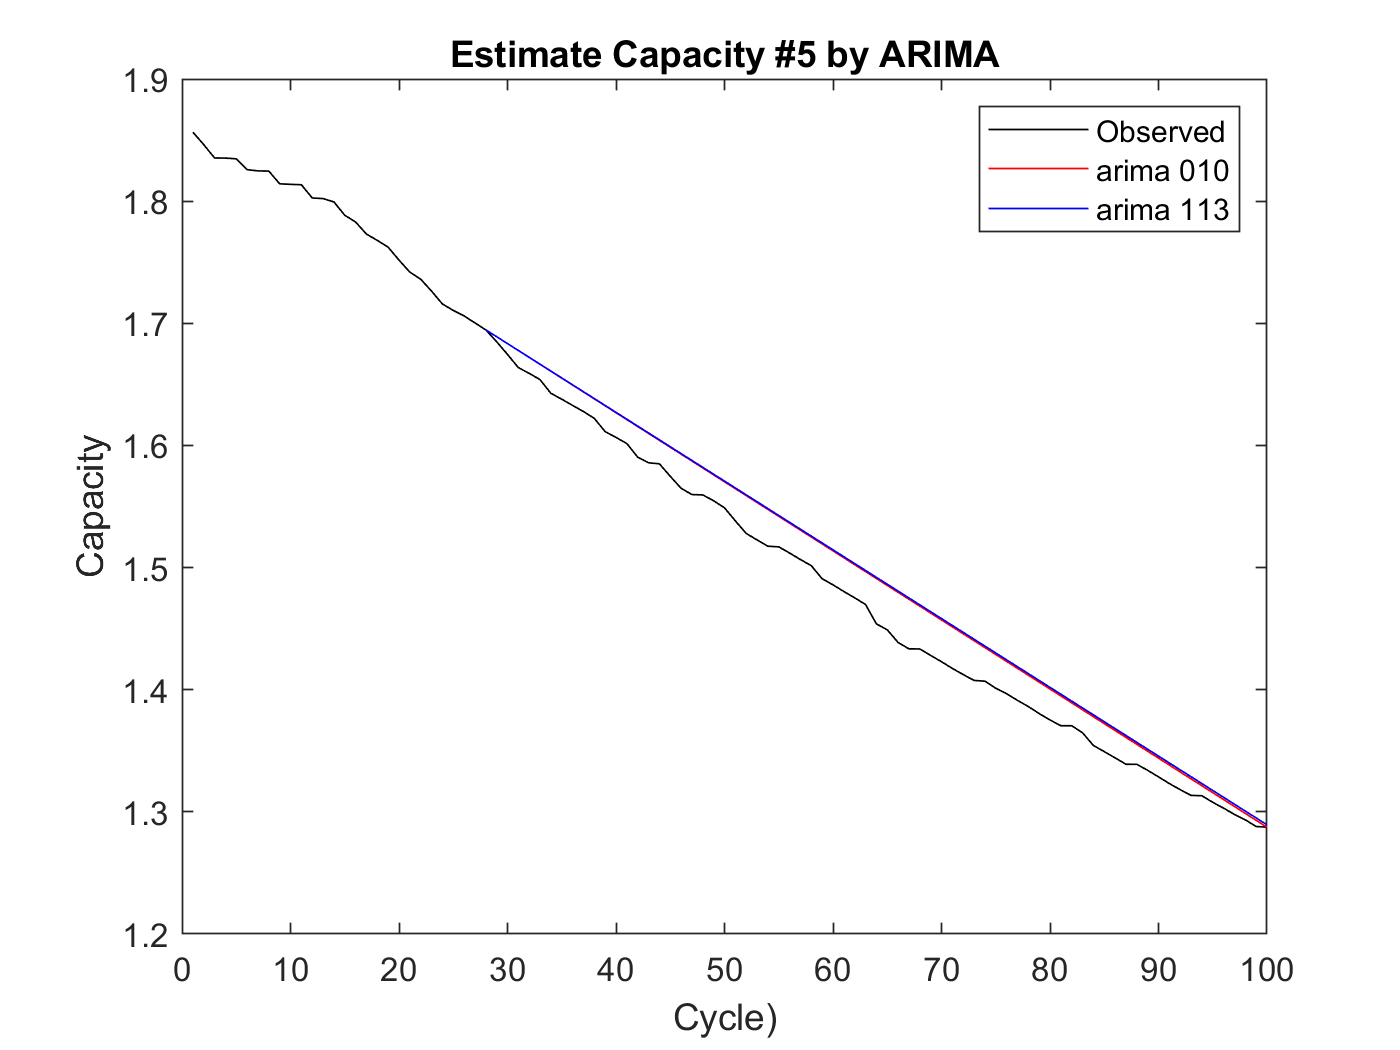




figure
plot(Y5,'k');
hold on
plot([(learning_end_index+1):end_index],yf5_base,'r');
plot([(learning_end_index+1):end_index],yf5_opt,'b');
%plot([(learning_end_index+1):end_index],yf223,'g');
legend("Observed","arima 010", 'arima 113')%,"arima_223")
title("Estimate Capacity #5 by ARIMA")
xlabel("Cycle)")
ylabel("Capacity")
hold off

% battery 6 - arima 312
earning_end_index = 27;
est_length = length(Y6) - learning_end_index;
end_index = length(Y6);

idxpre = 1:learning_end_index;
idxest = (learning_end_index+1):end_index;
% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl6_base = arima(0,1,0);
Mdl6_opt = arima(3,1,2);  % 0 1 0

EstMdl6_base = estimate(Mdl6_base,Y6(idxest),'Y0',Y6(idxpre));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0071336     0.00062538       -11.407      3.8681e-30
    Variance       2.2e-05     3.2077e-06        6.8586      6.9523e-12



EstMdl6_opt = estimate(Mdl6_opt,Y6(idxest),'Y0',Y6(idxpre));

 
    ARIMA(3,1,2) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic      PValue  
                ___________    _____________    __________    __________

    Constant    -0.00016301     8.3607e-05        -1.9498       0.051204
    AR{1}            1.5071        0.16475         9.1478     5.8117e-20
    AR{2}          -0.46419        0.27863         -1.666        0.09572
    AR{3}         -0.067916        0.14132       -0.48059        0.63081
    MA{1}           -1.9318       0.049833        -38.765              0
    MA{2}                 1       0.049148         20.347     4.9532e-92
    Variance     1.4632e-05     2.2028e-06         6.6425     3.0851e-11




%yf6_pre = Y6(idxpre(end - 1:end));
yf6_pre = Y6(idxpre(1:end));

yf6_base = forecast(EstMdl6_base,est_length,yf6_pre);
yf6_opt = forecast(EstMdl6_opt,est_length,yf6_pre);


%Plot the first xxx observations and the forecasts.
EstMdl6_base

EstMdl6_base =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: -0.00713359
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 2.20003e-05

EstMdl6_opt

EstMdl6_opt =   arima with properties:

     Description: "ARIMA(3,1,2) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 4
               D: 1
               Q: 2
        Constant: -0.000163015
              AR: {1.50711 -0.464195 -0.0679159} at lags [1 2 3]
             SAR: {}
              MA: {-1.93179 1} at lags [1 2]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.46318e-05

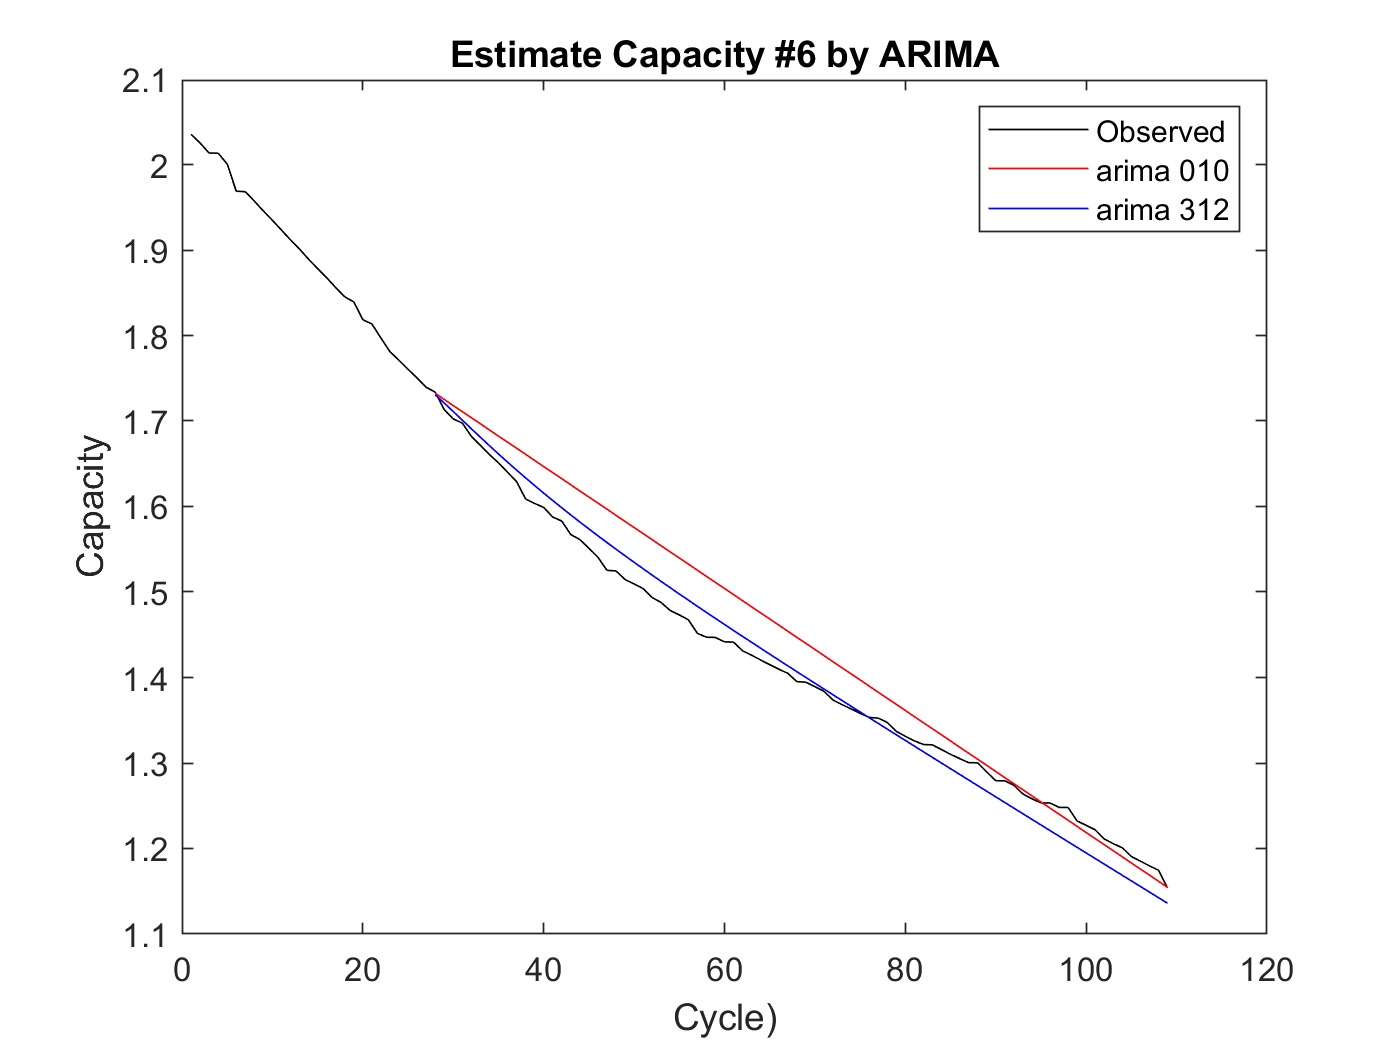




figure
plot(Y6,'k');
hold on
plot([(learning_end_index+1):end_index],yf6_base,'r');
plot([(learning_end_index+1):end_index],yf6_opt,'b');
legend("Observed","arima 010", 'arima 312')
title("Estimate Capacity #6 by ARIMA")
xlabel("Cycle)")
ylabel("Capacity")
hold off

% battery 56 - arima 313

%result_05_06_patten_change = [27 31];
%result_06_05_patten_change = [30 27];

% to get EstMdl65_base to use 56
learning_end_index = 30;
est_length = length(Y65) - learning_end_index;
end_index = length(Y65);

idxpre = 1:learning_end_index;
idxest = (learning_end_index+1):end_index;
% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl65_base = arima(0,1,0);



EstMdl65_base = estimate(Mdl65_base,Y65(idxest),'Y0',Y65(idxpre));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0055782     0.00038421       -14.519      9.2096e-48
    Variance    9.4919e-06     8.0535e-07        11.786      4.6064e-32




learning_end_index = 27;
est_length = length(Y56) - learning_end_index;
end_index = length(Y56);

idxpre = 1:learning_end_index;
idxest = (learning_end_index+1):end_index;
% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl56_base = arima(0,1,0);
Mdl56_opt = arima(3,1,3);  


EstMdl56_base = estimate(Mdl56_base,Y56(idxest),'Y0',Y56(idxpre));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0068941     0.00059742        -11.54      8.2994e-31
    Variance    2.0268e-05     2.9019e-06        6.9843      2.8624e-12



EstMdl56_opt = estimate(Mdl56_opt,Y56(idxest),'Y0',Y56(idxpre));

 
    ARIMA(3,1,3) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0069715      0.0099752        -0.69889       0.48462
    AR{1}                0         1.5803               0             1
    AR{2}                0         1.3276               0             1
    AR{3}            2e-12        0.99273      2.0146e-12             1
    MA{1}         -0.03757         1.5848       -0.023707       0.98109
    MA{2}         0.096133         1.3396        0.071761       0.94279
    MA{3}           0.1341         1.1521          0.1164       0.90734
    Variance    1.9493e-05 


%yf56_pre = Y56(idxpre(end - 1:end)); % error - Y0 at least 4
yf56_pre = Y56(idxpre(1:end)); 
yf56_base = forecast(EstMdl56_base,est_length,yf56_pre);
yf56_opt = forecast(EstMdl56_opt,est_length,yf56_pre);
yf56_by_5 = forecast(EstMdl5_base,est_length,yf56_pre);
yf56_by_6 = forecast(EstMdl6_base,est_length,yf56_pre);
yf56_by_65 = forecast(EstMdl65_base,est_length,yf56_pre);
EstMdl56_base

EstMdl56_base =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: -0.00689414
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 2.02681e-05

EstMdl56_opt

EstMdl56_opt =   arima with properties:

     Description: "ARIMA(3,1,3) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 4
               D: 1
               Q: 3
        Constant: -0.0069715
              AR: {2e-12} at lag [3]
             SAR: {}
              MA: {-0.0375696 0.0961333 0.134101} at lags [1 2 3]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 1.94928e-05

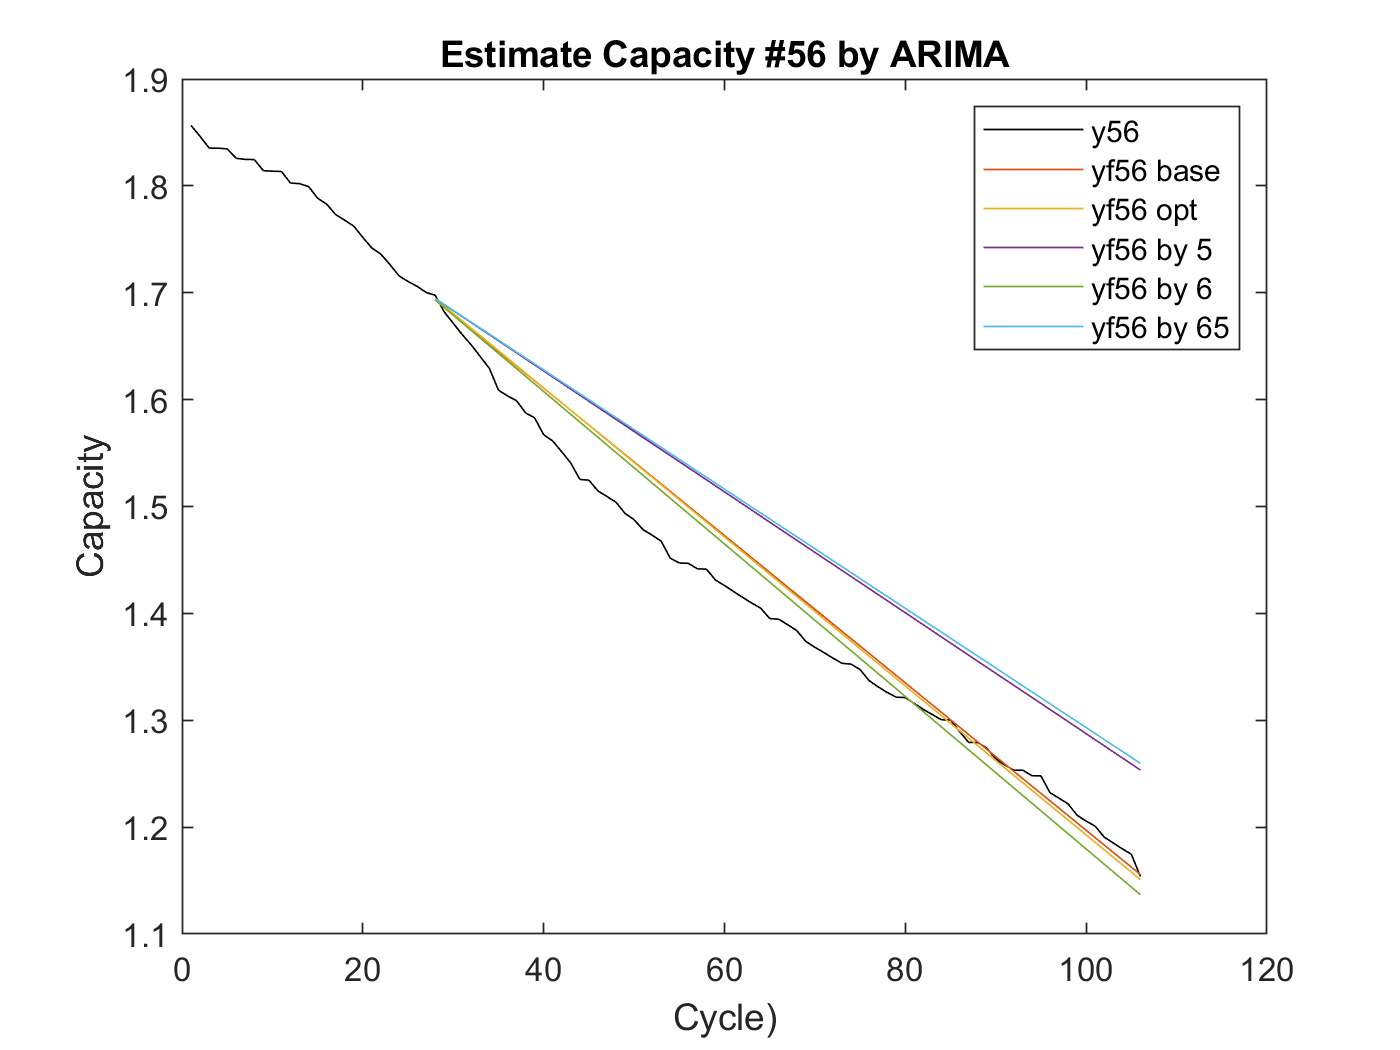


figure
plot(Y56,'k');
hold on
plot([(learning_end_index+1):end_index],yf56_base);
plot([(learning_end_index+1):end_index],yf56_opt);
plot([(learning_end_index+1):end_index],yf56_by_5);
plot([(learning_end_index+1):end_index],yf56_by_6);
plot([(learning_end_index+1):end_index],yf56_by_65);
legend('y56','yf56 base','yf56 opt','yf56 by 5','yf56 by 6','yf56 by 65')
title("Estimate Capacity #56 by ARIMA")
xlabel("Cycle)")
ylabel("Capacity")
hold off

% battery 65   arima 111
%result_05_06_patten_change = [27 31];
%result_06_05_patten_change = [30 27];

learning_end_index = 30;
est_length = length(Y65) - learning_end_index;
end_index = length(Y65);

idxpre = 1:learning_end_index;
idxest = (learning_end_index+1):end_index;
% ARIMA 모델에 적당하다. PCF Die out PACF Die out 
Mdl65_base = arima(0,1,0);
Mdl65_opt = arima(1,1,1);  


EstMdl65_base = estimate(Mdl65_base,Y65(idxest),'Y0',Y65(idxpre));

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0055782     0.00038421       -14.519      9.2096e-48
    Variance    9.4919e-06     8.0535e-07        11.786      4.6064e-32



EstMdl65_opt = estimate(Mdl65_opt,Y65(idxest),'Y0',Y65(idxpre));

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0082489      0.0015887       -5.1923       2.077e-07
    AR{1}         -0.46466        0.25553       -1.8184        0.069001
    MA{1}          0.64129        0.22048        2.9086       0.0036302
    Variance     9.048e-06     7.2365e-07        12.503      7.1627e-36




%yf56_pre = Y65(idxpre(end - 1:end)); % error - Y0 at least 4
yf65_pre = Y65(idxpre(1:end)); 
yf65_base = forecast(EstMdl65_base,est_length,yf65_pre);
yf65_opt = forecast(EstMdl65_opt,est_length,yf65_pre);
yf65_by_5 = forecast(EstMdl5_base,est_length,yf65_pre);
yf65_by_6 = forecast(EstMdl6_base,est_length,yf65_pre);
yf65_by_56 = forecast(EstMdl56_base,est_length,yf65_pre);

EstMdl65_base

EstMdl65_base =   arima with properties:

     Description: "ARIMA(0,1,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 1
               D: 1
               Q: 0
        Constant: -0.00557824
              AR: {}
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 9.49189e-06

EstMdl65_opt

EstMdl65_opt =   arima with properties:

     Description: "ARIMA(1,1,1) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 2
               D: 1
               Q: 1
        Constant: -0.00824894
              AR: {-0.464662} at lag [1]
             SAR: {}
              MA: {0.641295} at lag [1]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 9.04799e-06

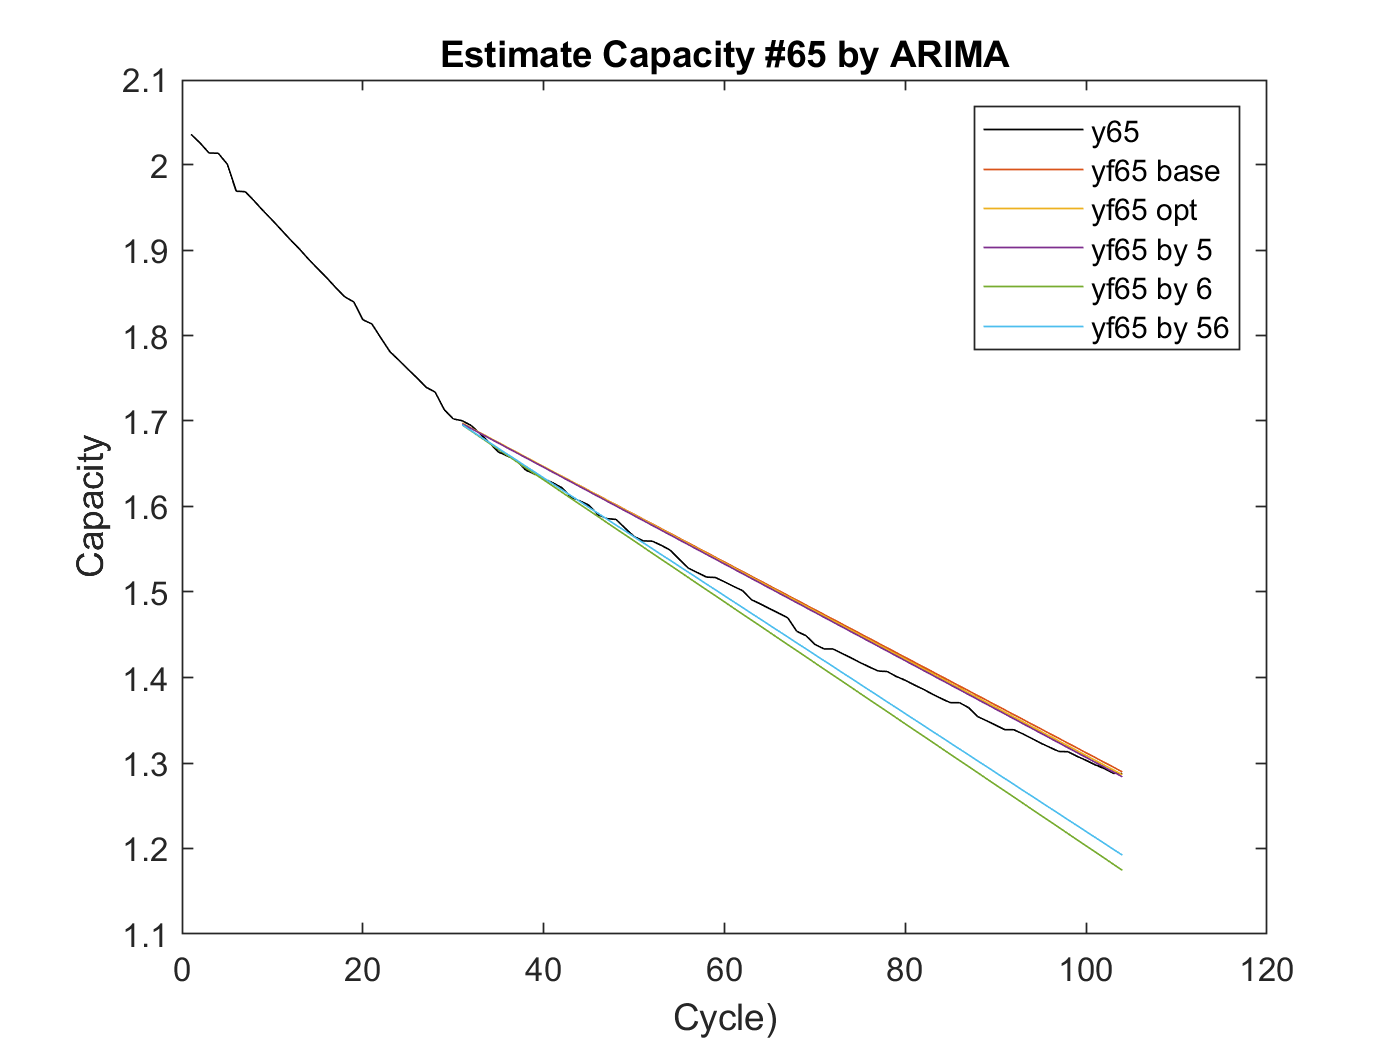


figure
plot(Y65,'k');
hold on
plot([(learning_end_index+1):end_index],yf65_base);
plot([(learning_end_index+1):end_index],yf65_opt);
plot([(learning_end_index+1):end_index],yf65_by_5);
plot([(learning_end_index+1):end_index],yf65_by_6);
plot([(learning_end_index+1):end_index],yf65_by_56);
title("Estimate Capacity #65 by ARIMA")
legend('y65','yf65 base','yf65 opt','yf65 by 5','yf65 by 6','yf65 by 56')
xlabel("Cycle)")
ylabel("Capacity")
hold off

RMSE

%{
RMSE_5_by_5 = sqrt(mean(( Y5' - yf5_opt' ).^2))
RMSE_6_by_6 = sqrt(mean(( Y6' - yf6_opt' ).^2))
RMSE_56_by_05 = sqrt(mean(( Y56' - yf56_by_5 ).^2))
RMSE_56_by_06 = sqrt(mean(( Y56' - yf56_by_6 ).^2))
RMSE_65_by_05 = sqrt(mean(( Y65' - yf65_by_5 ).^2))
RMSE_65_by_06 = sqrt(mean(( Y65' - yf65_by_6 ).^2))
%}

%result_05_06_patten_change = [27 31];
%result_06_05_patten_change = [30 27];
change_index_05_06 = 28; % last + 1
change_index_06_05 = 31;

RMSE_56_by_05 = sqrt(mean(( Y56(change_index_05_06:end) - yf56_by_5 ).^2))

RMSE_56_by_05 = 0.0767

RMSE_56_by_06 = sqrt(mean(( Y56(change_index_05_06:end) - yf56_by_6 ).^2))

RMSE_56_by_06 = 0.0309

RMSE_65_by_05 = sqrt(mean(( Y65(change_index_06_05:end) - yf65_by_5 ).^2))

RMSE_65_by_05 = 0.0203

RMSE_65_by_06 = sqrt(mean(( Y65(change_index_06_05:end) - yf65_by_6 ).^2))

RMSE_65_by_06 = 0.0501

ARIMA 자료 

[https://kr.mathworks.com/help/predmaint/ug/predict-remaining-cycle-life-of-batteries-from-initial-operation-data.html](https://kr.mathworks.com/help/predmaint/ug/predict-remaining-cycle-life-of-batteries-from-initial-operation-data.html)

# 초기 작동 데이터에서 배터리 사이클 수명 예측

[https://kr.mathworks.com/help/predmaint/ug/nonlinear-state-estimation-of-a-degrading-battery-system.html](https://kr.mathworks.com/help/predmaint/ug/nonlinear-state-estimation-of-a-degrading-battery-system.html)

# 성능 저하 중인 배터리 시스템의 비선형 상태 추정

[https://kr.mathworks.com/help/predmaint/ug/remaining-useful-life-estimation-using-convolutional-neural-network.html](https://kr.mathworks.com/help/predmaint/ug/remaining-useful-life-estimation-using-convolutional-neural-network.html)

# Remaining Useful Life Estimation using Convolutional Neural Network

[https://www.mdpi.com/1996-1073/11/4/820/htm#](https://www.mdpi.com/1996-1073/11/4/820/htm#)

settings

Open AccessArticle

# Novel Approach for Lithium-Ion Battery On-Line Remaining Useful Life Prediction Based on Permutation Entropy

[https://github.com/danzhaozju/Energy-Revenue-Optimizing/blob/master/Final%20Report.pdf](https://github.com/danzhaozju/Energy-Revenue-Optimizing/blob/master/Final%20Report.pdf)

[https://github.com/xingliuUT/battery_planner](https://github.com/xingliuUT/battery_planner)